## Pilot testing revisited: The HDG applied to a rotational Equation

### Exploring and review of the pilot example

A short overview by *@alujan*

clear
format short
syms x y z real

% Let's add to the path the src and drivers: Original Article
addpath('/Users/chubbs/Documents/UN/HDG/949_Sayas/Matlab/Transfer/Drivers/')
addpath('/Users/chubbs/Documents/UN/HDG/949_Sayas/Matlab/Transfer/Src/')
% Let's add the path of the gmsh structure: Load Mesh structure
addpath('/Users/chubbs/Documents/UN/HDG/gmsh')

% Let's add the path of the structures created: Curl definitions
addpath('/Users/chubbs/Documents/UN/HDG/949_Sayas/Matlab/Transfer/Unstable/')

#### Load of structures for analisys

Let's load the reference structres we're going to use to set the pilot example

% Importing of a singular structure for first case scenario: Unitary cube
T = load_mesh('cubeD0.msh')

 
Mesh Type
2.2 0 8


T = struct with fields:
    coordinates: [45×3 double]
       elements: [100×4 double]
      dirichlet: [0×3 double]
        neumann: [0×3 double]
          faces: [242×4 double]
       dirfaces: [1×0 double]
       neufaces: [1×0 double]
      facebyele: [100×4 double]
    orientation: [100×4 double]
           perm: [100×4 double]
         volume: [100×1 double]
           area: [242×1 double]
        normals: [100×12 double]


% Listing of elements for growth of method testing
listT = {T};

This have really improtant information about the geometry, for instance let's take an indepth.

Let's validate the way this faces organice for instance in the nodes

T.faces(T.facebyele(1, 1), 1:3)

ans =     38    40    44


#### Additional analysis on the orientation definitions

For instance let's create the temporal parameters defined by `load_mesh`, in this case we define:

% - Initial definition of all faces list
% Construction of a list of all faces
shape=[1 3 2; ...
       1 2 4; ... % Notice that the faces 3 and 4 follows a different definition
       1 4 3; ... % Original definition: 1 3 4
       2 3 4];    % Original definition: 4 2 3

nelts=size(T.elements,1);
faces=zeros(4*nelts,3);
 for k=1:nelts
     nodes=T.elements(k,:);               %1x4
     faces(4*(k-1)+(1:4),:)=nodes(shape); % 1x3
 end

% Processing of faces
copyoffaces = faces          % 4 nelts x 3 (in local positive orientation)

copyoffaces =     38    40    44
    38    44    45
    38    45    40
    44    40    45
    24    22    35
    24    35    45
    24    45    22
    35    22    45
    32    24    35
    32    35    45


faces = sort(faces,2);      % Sort of faces values on incremental order: storage

% Matrix with orientations
A=T.facebyele';

% ALR: This is a really good way to find the faces in a sorted manner
faces = T.faces(A(:),1:3)    % Sorted definition of face

faces =     38    40    44
    38    44    45
    38    40    45
    40    44    45
    22    24    35
    24    35    45
    22    24    45
    22    35    45
    24    32    35
    32    35    45


With this two elements we want to validate if the face it's oriented positive in the faces structure, for instance we can do this process by using the idea:

% If the face it's oriented positive, copyoffaces must match the faces
% defintion:
level = 10;   % To see the effect consider the 
faces(level, :) == copyoffaces(level, :)

ans = 1×3 logical array
   0   0   1


Using this we can find if the face it's correctly oriented, furthermore we can inheribly define:

sum(faces(level, :) == copyoffaces(level, :),2)

ans = 1

unique(sum(faces==copyoffaces,2))

ans =      0
     1
     3


% This information per face let us create indices that can correct the
% orientations of the normal vectors depending of the orientation defined
t=sum(faces==copyoffaces,2)==ones(4*nelts,1)

t = 400×1 logical array
   0
   0
   1
   1
   1
   0
   0
   1
   1
   0


t=1-2*t,t=reshape(t,[4,nelts])

t =      1
     1
    -1
    -1
    -1
     1
     1
    -1
    -1
     1


t =      1    -1    -1    -1    -1    -1     1     1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1    -1     1    -1    -1     1     1     1     1     1     1    -1    -1    -1    -1     1     1    -1     1     1     1     1     1     1     1     1     1     1     1     1    -1
     1     1     1     1    -1     1    -1     1     1     1    -1     1     1    -1    -1    -1    -1     1    -1     1     1    -1     1     1    -1    -1    -1     1    -1    -1    -1    -1     1    -1     1     1     1     1     1     1    -1     1     1    -1     1    -1     1    -1     1     1
    -1     1     1    -1     1    -1    -1    -1    -1     1    -1    -1    -1     1    -1     1     1    -1     1     1    -1    -1     1    -1     1     1    -1    -1     1    -1     1     1    -1     1    -1    -1    -1    -1    -1    -1    -1    -1     1     1    -1    -1    -1     1    -1     1
    -1    -1    -1     1     1     1     1    -1    -1    -1     1     1    -1     1     1   

T.orientation=t';                % Elements for the normals orientations

Para validar la rotación y patrón de las caras *(orientación y permutación respectivamente),* primeramente debemos considerar la acción a realizar

% Matrix with permutation order
eq = @(u,v) sum(u==v,2)==3;  % Validation if two faces have equal orientations

rot=[1 2 3;...        % (s,t)          
     1 3 2;...        % (t,s) 
     3 1 2;...        % (t,1-s-t) 
     3 2 1;...        % (s,1-s-t) 
     2 3 1;...        % (1-s-t,s) 
     2 1 3];          % (1-s-t,t) 

pattern=[1 2 3;...    % (s,t,0)
         1 2 4;...    % (s,0,t)
         1 3 4;...    % (0,s,t)
         4 2 3];      % (s,t,1-s-t)

% For this minimal case consider the validation of pattern:
level = 1;  % Compare only between pemutation 1

% Computation of [1, 2, 3] vs. [1, 2, 3]
eq(rot(level, :), pattern(1, :))

ans = logical
   1


level = 5;  % Compare only between pemutation 1

% Computation of [2, 3, 1] vs. [1, 2, 3]
eq(rot(level, :), pattern(1, :))

ans = logical
   0


With this idea on mind, if we generalize this consideration we got:

% Let's consider just the third face
level = 3; face_id = 100;

face_global = T.faces(T.facebyele(face_id,level),1:3)

face_global =     14    29    41


faceLocal =T.elements(face_id,pattern(level,:))

faceLocal =     29    41    14


% Now what we want to know it's which permutation it' valid to go from the
% local value to the global value
faceLocal(rot) % List over all the possible values that the faces can take

ans =     29    41    14
    29    14    41
    14    29    41
    14    41    29
    41    14    29
    41    29    14


% ALR: Ideas on the global definition for A_0 & A_1
level = 1; nodes = T.elements(level,:);

% Positive orientation of the face
orientation = 1;

% Global positive orientation of the face
face_positive = nodes(shape(orientation, :))

face_positive =     38    40    44


% Recall of the coordinates positively oriented
face_vectors = T.coordinates(face_positive, :)

face_vectors =     0.3750         0    0.6250
    0.7188         0    0.7188
    0.7187    0.2812    1.0000


% For instance in this case we can now define:
A1 = face_vectors(3, :) - face_vectors(1, :)

A1 =     0.3437    0.2812    0.3750


A0 = face_vectors(2, :) - face_vectors(1, :)

A0 =     0.3437         0    0.0937


This definitions are the global coordinates of the face defined, not after defining the corresponding permutation, we want to find the needed change to describe $A=\left\lbrack A_1 \;|\;A_0 \right\rbrack$

Now we're looking forward to define this vectors as a uniqye element for each face, for instance consider:

% Definition of additional parameters
Nfaces = size(T.faces, 1);

% Extraction of the nodes per faces
A = T.faces(:,1:3)';

% Definition of the coordinates per node per face
nodes = reshape(T.coordinates(A(:), :)', [3, 3, Nfaces]);
% Computation of A_1 and A_0 per face: [A_1 | A_0]
A = zeros([2, 3, Nfaces]);

A(1, :, :) = nodes(:, 3, :) - nodes(:, 1, :);  % A_1
A(2, :, :) = nodes(:, 2, :) - nodes(:, 1, :);  % A_0

% Validation of access for the values needed
% - For instance let's consider the values of these
% Vectors for the element
element = 69; face_selector = 3;

% - Element selection: 
A_ref = T.coordinates(T.faces(T.facebyele(element, face_selector), 1:3), :);
A_ref(3, :) - A_ref(1, :), A_ref(2, :) - A_ref(1, :)

ans =   -1.2500e-01  -3.7500e-01   2.5000e-01


ans =   -3.7500e-01  -2.9297e-02   3.4570e-01


A(:, :, T.facebyele(element, face_selector))

ans =   -1.2500e-01  -3.7500e-01   2.5000e-01
  -3.7500e-01  -2.9297e-02   3.4570e-01


% - Storage of structure
T.A = A

T = struct with fields:
    coordinates: [45×3 double]
       elements: [100×4 double]
      dirichlet: [0×3 double]
        neumann: [0×3 double]
          faces: [242×4 double]
       dirfaces: [1×0 double]
       neufaces: [1×0 double]
      facebyele: [100×4 double]
    orientation: [100×4 double]
           perm: [100×4 double]
         volume: [100×1 double]
           area: [242×1 double]
        normals: [100×12 double]
              A: [2×3×242 double]


T.A(:, :, T.facebyele(:, 1))

ans = ans(:,:,1) =

    0.3437    0.2812    0.3750
    0.3437         0    0.0937


ans(:,:,2) =

   -0.3750    0.3437    0.2813
   -0.0938    0.3437         0


ans(:,:,3) =

   -0.2812   -0.0000    0.2813
    0.0645    0.2813    0.3457


ans(:,:,4) =

    0.2937    0.3469    0.3490
    0.2937   -0.0437    0.2500


ans(:,:,5) =

   -0.2813   -0.0938    0.3750
   -0.2812   -0.3750    0.0937


ans(:,:,6) =

    0.0437   -0.2937    0.2500
    0.3750         0   -0.1250


ans(:,:,7) =

    0.0437   -0.2937    0.2500
   -0.2500   -0.3750   -0.1250


ans(:,:,8) =

   -0.0656   -0.2938    0.3490
    0.2937   -0.0437    0.2500


ans(:,:,9) =

    0.3750   -0.2500   -0.1250
         0    0.0957   -0.4043


ans(:,:,10) =

   -0.3750   -0.0293    0.3457
   -0.3750    0.3437    0.2813


ans(:,:,11) =

    0.3750   -0.3457    0.2793
    0.2500   -0.3457   -0.0957


ans(:,:,12) =

    0.3437    0.2812    0.3750
   -0.0000    0.3750    0.3750


ans(:,:,13) =

   -0.2500   -0.3750   -0.1250
    0.095

And we can clearly see that this definition creates a big disruption between the values compared.

For instance, consider that we can define globally $A_0 ,A_1$.

shape_face = shape'; shape_face = shape_face(:)'

shape_face =      1     3     2     1     2     4     1     4     3     2     3     4


For instance, consider that we can define globally $A_0 ,A_1$.

shape_face = shape'; shape_face = shape_face(:)'

shape_face =      1     3     2     1     2     4     1     4     3     2     3     4


% Global definition of nodes
nodes = T.elements;

% Global definition of all positive oriented faces, no we can define all
% the positevely oriented coordinates
positive_nodes = nodes(:, shape_face)

positive_nodes =     38    40    44    38    44    45    38    45    40    44    40    45
    24    22    35    24    35    45    24    45    22    35    22    45
    32    24    35    32    35    45    32    45    24    35    24    45
    21    27    25    21    25    45    21    45    27    25    27    45
    44    40    26    44    26    45    44    45    40    26    40    45
    29    41    30    29    30    45    29    45    41    30    41    45
    34    41    29    34    29    45    34    45    41    29    41    45
    21    25    39    21    39    45    21    45    25    39    25    45
    33    36    38    33    38    45    33    45    36    38    36    45
    35    22    36    35    36    45    35    45    22    36    22    45


% We can now define the positions of the elements for each vector
v1_positions = (0:3) * 3 + 1;
v2_positions = (0:3) * 3 + 2;
v3_positions = (0:3) * 3 + 3;

% Now here is defined the different positions for each vector
positive_oriented_v1 = T.coordinates(positive_nodes(:, v1_positions), :)';
positive_oriented_v1 = reshape(positive_oriented_v1, [4*3, nelts])'

positive_oriented_v1 =     0.3750         0    0.6250    0.2812    0.7187         0    0.3457    1.0000    0.3457    0.7063    0.2938         0
    0.7187    0.2812    1.0000    0.2500    1.0000    0.7500         0    0.6250    0.6250    0.7063    0.2938         0
         0    0.2500    0.7500         0    0.7187    0.2813    0.2500         0    0.2500    0.3750         0    0.6250
    0.2500    1.0000    0.7500    0.2500         0    0.2500    0.2938    0.7063    1.0000    0.3457    1.0000    0.3457
    0.3457    1.0000    0.3457    0.7187    0.2812    1.0000    0.2812    0.7187         0    0.2500         0    0.2500
    0.3457    1.0000    0.3457    0.3750         0    0.6250         0    0.6250    0.6250    1.0000    0.3750    0.6250
    1.0000    0.6406    0.3490    0.7187    0.2812    1.0000    1.0000    0.3750    0.6250         0    0.2500    0.7500
    0.6479    0.6437    1.0000    0.6250    1.0000    0.6250    0.6250    1.0000    0.6250    0.7187    1.0000    0.2813
         

positive_oriented_v2 = T.coordinates(positive_nodes(:, v2_positions), :)';
positive_oriented_v2 = reshape(positive_oriented_v2, [4*3, nelts])'

positive_oriented_v2 =     0.7188         0    0.7188    0.3750    0.3750         0    0.2812    0.7187         0    1.0000    0.6406    0.3490
    0.7188         0    0.7188    0.2938    0.7063    1.0000    0.2938    0.7063    1.0000    1.0000    0.2500    0.2500
         0    0.3457    0.3457    0.3750    0.3750         0    0.3750         0    0.6250    0.7187    0.2812    1.0000
    0.3457    1.0000    0.3457         0    0.3457    0.3457    0.6479    0.6437    1.0000    0.7187    1.0000    0.2813
    0.6437    0.6479         0    0.3750         0    0.6250    0.3750    0.3750         0    0.3750    0.3750         0
         0    0.7187    0.2813    0.3750    0.3750    1.0000         0    0.2500    0.7500    0.7188         0    0.7188
    0.7063    0.2938         0    1.0000    0.3750    0.6250    0.6406         0    0.3490         0    0.6250    0.6250
    1.0000    0.3750    0.6250    0.6479    0.6437    1.0000    1.0000    0.7188    0.7188    1.0000    0.6406    0.3490
    0.375

positive_oriented_v3 = T.coordinates(positive_nodes(:, v3_positions), :)';
positive_oriented_v3 = reshape(positive_oriented_v3, [4*3, nelts])'

positive_oriented_v3 =     0.7187    0.2812    1.0000         0    0.7187    0.2813         0    0.7187    0.2813    1.0000    0.2500    0.2500
    1.0000    0.3750    0.6250    0.6250    1.0000    0.6250    0.2500    1.0000    0.7500    0.6406         0    0.3490
    0.3750         0    0.6250         0    0.3457    0.3457         0    0.3457    0.3457    0.3750    0.3750    1.0000
         0    0.6250    0.6250    0.3750    0.3750         0    0.6250    1.0000    0.6250    0.6437    0.6479         0
    0.2812    0.7187         0    0.5000         0    1.0000         0    0.5000         0    0.6406         0    0.3490
         0    0.6250    0.6250         0    0.2500    0.7500    0.3750    0.3750    1.0000    0.6406         0    0.3490
    0.6437    0.6479         0    0.6479    0.6437    1.0000    1.0000    0.2500    0.2500         0    0.3457    0.3457
    1.0000    0.7188    0.7188    1.0000    0.7188    0.7188    1.0000    0.6406    0.3490    0.6437    0.6479         0
    0.293

% Finally with these elements we can define for all elements the global A1
% and A0 components similar to the normals definitions
A1 = positive_oriented_v3 - positive_oriented_v1

A1 =     0.3437    0.2812    0.3750   -0.2812   -0.0000    0.2813   -0.3457   -0.2813   -0.0645    0.2937   -0.0437    0.2500
    0.2813    0.0938   -0.3750    0.3750         0   -0.1250    0.2500    0.3750    0.1250   -0.0656   -0.2938    0.3490
    0.3750   -0.2500   -0.1250         0   -0.3730    0.0645   -0.2500    0.3457    0.0957   -0.0000    0.3750    0.3750
   -0.2500   -0.3750   -0.1250    0.1250    0.3750   -0.2500    0.3312    0.2937   -0.3750    0.2980   -0.3521   -0.3457
   -0.0645   -0.2813   -0.3457   -0.2188   -0.2812         0   -0.2812   -0.2188         0    0.3906         0    0.0990
   -0.3457   -0.3750    0.2793   -0.3750    0.2500    0.1250    0.3750   -0.2500    0.3750   -0.3594   -0.3750   -0.2760
   -0.3563    0.0073   -0.3490   -0.0708    0.3625         0         0   -0.1250   -0.3750         0    0.0957   -0.4043
    0.3521    0.0750   -0.2812    0.3750   -0.2812    0.0937    0.3750   -0.3594   -0.2760   -0.0750   -0.3521   -0.2813
    0.2938    0.0813    0.3

A0 = positive_oriented_v2 - positive_oriented_v1

A0 =     0.3437         0    0.0937    0.0938   -0.3437         0   -0.0645   -0.2813   -0.3457    0.2937    0.3469    0.3490
    0.0000   -0.2812   -0.2812    0.0437   -0.2937    0.2500    0.2938    0.0813    0.3750    0.2937   -0.0437    0.2500
         0    0.0957   -0.4043    0.3750   -0.3437   -0.2813    0.1250         0    0.3750    0.3437    0.2812    0.3750
    0.0957         0   -0.4043   -0.2500    0.3457    0.0957    0.3542   -0.0625         0    0.3730         0   -0.0645
    0.2980   -0.3521   -0.3457   -0.3437   -0.2812   -0.3750    0.0938   -0.3437         0    0.1250    0.3750   -0.2500
   -0.3457   -0.2813   -0.0645   -0.0000    0.3750    0.3750         0   -0.3750    0.1250   -0.2812   -0.3750    0.0937
   -0.2937   -0.3469   -0.3490    0.2813    0.0938   -0.3750   -0.3594   -0.3750   -0.2760         0    0.3750   -0.1250
    0.3521   -0.2687   -0.3750    0.0229   -0.3563    0.3750    0.3750   -0.2812    0.0937    0.2813   -0.3594    0.0677
    0.3750   -0.2500    0.3

Now for all the elements we might define:

orient=zeros(nelts,4);

% Faces definition per all elements
for f=1:4 
    faceGlobal=T.faces(T.facebyele(:,f),1:3);
    faceLocal =T.elements(:,pattern(f,:));

    % The identifier it's the direct value in which the permutation finds
    % the orientation.
    for j=1:6    
        orient(:,f) = orient(:,f)+j*eq(faceGlobal,faceLocal(:,rot(j,:)));
    end
end
T.perm=orient;

#### Definitions of reference solutions

First let's define the values we're going to compare with, in this case the functions $u$ and $z$, defined for the auxiliar equation:


$$z-\nabla \times u=0\;\textrm{in}\;\Omega$$



$$u+\nabla \times z=f\;\textrm{in}\;\Omega$$



$$u\times n=g\times n\;\textrm{on}\;\partial \Omega$$


Take in mind this a vectorial PDE, for this scenario every evaluation of the values must be in components of the vector

% Let's define a simple value for U: harmonic vector
Ux = sin(pi*x)*sin(pi*y)*sin(pi*z); Uy = sin(2*pi*x)*sin(2*pi*y)*sin(2*pi*z); Uz = sin(3*pi*x)*sin(3*pi*y)*sin(3*pi*z);

U(x, y, z) = [Ux; Uy; Uz]

$$U(x, y, z) = \left(\begin{array}{c} \sin\left(\pi \,x\right)\,\sin\left(\pi \,y\right)\,\sin\left(\pi \,z\right)\\ \sin\left(2\,\pi \,x\right)\,\sin\left(2\,\pi \,y\right)\,\sin\left(2\,\pi \,z\right)\\ \sin\left(3\,\pi \,x\right)\,\sin\left(3\,\pi \,y\right)\,\sin\left(3\,\pi \,z\right) \end{array}\right)$$

% Partial derivarives of the component
Uxy = diff(Ux, y); Uxz = diff(Ux, z);
Uyx = diff(Uy, x); Uyz = diff(Uy, z);
Uzx = diff(Uz, x); Uzy = diff(Uz, y);

% Definition of auxiliar variable: Z
Zx = Uzy - Uyz; Zy = Uxz - Uzx; Zz = Uyx - Uxy;

Z(x, y, z) = [Zx; Zy; Zz]

$$Z(x, y, z) = \begin{array}{l} \left(\begin{array}{c} 3\,\pi \,\cos\left(3\,\pi \,y\right)\,\sin\left(3\,\pi \,x\right)\,\sigma_{1}-2\,\pi \,\cos\left(2\,\pi \,z\right)\,\sin\left(2\,\pi \,x\right)\,\sigma_{2}\\ \pi \,\cos\left(\pi \,z\right)\,\sin\left(\pi \,x\right)\,\sin\left(\pi \,y\right)-3\,\pi \,\cos\left(3\,\pi \,x\right)\,\sin\left(3\,\pi \,y\right)\,\sigma_{1}\\ 2\,\pi \,\cos\left(2\,\pi \,x\right)\,\sigma_{2}\,\sin\left(2\,\pi \,z\right)-\pi \,\cos\left(\pi \,y\right)\,\sin\left(\pi \,x\right)\,\sin\left(\pi \,z\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(3\,\pi \,z\right)\\ \sigma_{2}=\sin\left(2\,\pi \,y\right) \end{array}$$

% Partial derivarives of the component
Zxy = simplify(diff(Zx, y)); Zxz = simplify(diff(Zx, z));
Zyx = simplify(diff(Zy, x)); Zyz = simplify(diff(Zy, z));
Zzx = simplify(diff(Zz, x)); Zzy = simplify(diff(Zz, y));

% Definition of curl vector of Z: curlZ
curlZx = Zzy - Zyz; curlZy = Zxz - Zzx; curlZz = Zyx - Zxy;

curlZ = [curlZx; curlZy; curlZz]

$$curlZ = \begin{array}{l} \left(\begin{array}{c} 4\,\pi^{2}\,\cos\left(2\,\pi \,x\right)\,\sigma_{6}\,\sigma_{1}+9\,\pi^{2}\,\cos\left(3\,\pi \,x\right)\,\sigma_{5}\,\sigma_{2}+2\,\pi^{2}\,\sin\left(\pi \,x\right)\,\sin\left(\pi \,y\right)\,\sin\left(\pi \,z\right)\\ \pi^{2}\,\cos\left(\pi \,x\right)\,\cos\left(\pi \,y\right)\,\sin\left(\pi \,z\right)+9\,\pi^{2}\,\cos\left(3\,\pi \,y\right)\,\sigma_{5}\,\sigma_{3}+8\,\pi^{2}\,\sigma_{4}\,\sin\left(2\,\pi \,y\right)\,\sigma_{1}\\ \pi^{2}\,\cos\left(\pi \,x\right)\,\cos\left(\pi \,z\right)\,\sin\left(\pi \,y\right)+4\,\pi^{2}\,\sigma_{6}\,\cos\left(2\,\pi \,z\right)\,\sigma_{4}+18\,\pi^{2}\,\sigma_{3}\,\sigma_{2}\,\sin\left(3\,\pi \,z\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,\pi \,z\right)\\ \sigma_{2}=\sin\left(3\,\pi \,y\right)\\ \sigma_{3}=\sin\left(3\,\pi \,x\right)\\ \sigma_{4}=\sin\left(2\,\pi \,x\right)\\ \sigma_{5}=\cos\left(3\,\pi \,z\right)\\ \sigma_{6}=\cos\left(2\,\pi \,y\right) \end{array}$$

% Definition of forcement: F
Fx = Ux + curlZx; Fy = Uy + curlZy; Fz = Uz + curlZz;

F(x, y, z) = [Fx; Fy; Fz]

$$F(x, y, z) = \begin{array}{l} \left(\begin{array}{c} \sin\left(\pi \,x\right)\,\sin\left(\pi \,y\right)\,\sin\left(\pi \,z\right)+4\,\pi^{2}\,\cos\left(2\,\pi \,x\right)\,\sigma_{8}\,\sigma_{1}+9\,\pi^{2}\,\cos\left(3\,\pi \,x\right)\,\sigma_{7}\,\sigma_{2}+2\,\pi^{2}\,\sin\left(\pi \,x\right)\,\sin\left(\pi \,y\right)\,\sin\left(\pi \,z\right)\\ \sigma_{4}\,\sigma_{6}\,\sigma_{1}+\pi^{2}\,\cos\left(\pi \,x\right)\,\cos\left(\pi \,y\right)\,\sin\left(\pi \,z\right)+9\,\pi^{2}\,\cos\left(3\,\pi \,y\right)\,\sigma_{7}\,\sigma_{3}+8\,\pi^{2}\,\sigma_{4}\,\sigma_{6}\,\sigma_{1}\\ \sigma_{3}\,\sigma_{2}\,\sigma_{5}+\pi^{2}\,\cos\left(\pi \,x\right)\,\cos\left(\pi \,z\right)\,\sin\left(\pi \,y\right)+4\,\pi^{2}\,\sigma_{8}\,\cos\left(2\,\pi \,z\right)\,\sigma_{4}+18\,\pi^{2}\,\sigma_{3}\,\sigma_{2}\,\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,\pi \,z\right)\\ \sigma_{2}=\sin\left(3\,\pi \,y\right)\\ \sigma_{3}=\sin\left(3\,\pi \,x\right)\\ \sigma_{4}=\sin\left(2\,\pi \,x\right)\\ \sigma_{5}=\sin\left(3\,\pi \,z\right)\\ \sigma_{6}=\sin\left(2\,\pi \,y\right)\\ \sigma_{7}=\cos\left(3\,\pi \,z\right)\\ \sigma_{8}=\cos\left(2\,\pi \,y\right) \end{array}$$

% Definition of g element: Dirichlet condition G
Gx = Ux; Gy = Uy; Gz = Uz;

G(x, y, z) = [Gx; Gy; Gz]

$$G(x, y, z) = \left(\begin{array}{c} \sin\left(\pi \,x\right)\,\sin\left(\pi \,y\right)\,\sin\left(\pi \,z\right)\\ \sin\left(2\,\pi \,x\right)\,\sin\left(2\,\pi \,y\right)\,\sin\left(2\,\pi \,z\right)\\ \sin\left(3\,\pi \,x\right)\,\sin\left(3\,\pi \,y\right)\,\sin\left(3\,\pi \,z\right) \end{array}\right)$$

% Postprocessing of the resultant values
ux = matlabFunction(Ux, Vars={x, y, z});
uy = matlabFunction(Uy, Vars={x, y, z});
uz = matlabFunction(Uz, Vars={x, y, z});

fx = matlabFunction(Fx, Vars={x, y, z});
fy = matlabFunction(Fy, Vars={x, y, z});
fz = matlabFunction(Fz, Vars={x, y, z});

gx = matlabFunction(Gx, Vars={x, y, z});
gy = matlabFunction(Gy, Vars={x, y, z});
gz = matlabFunction(Gz, Vars={x, y, z});

zx = matlabFunction(Zx, Vars={x, y, z});
zy = matlabFunction(Zy, Vars={x, y, z});
zz = matlabFunction(Zz, Vars={x, y, z});

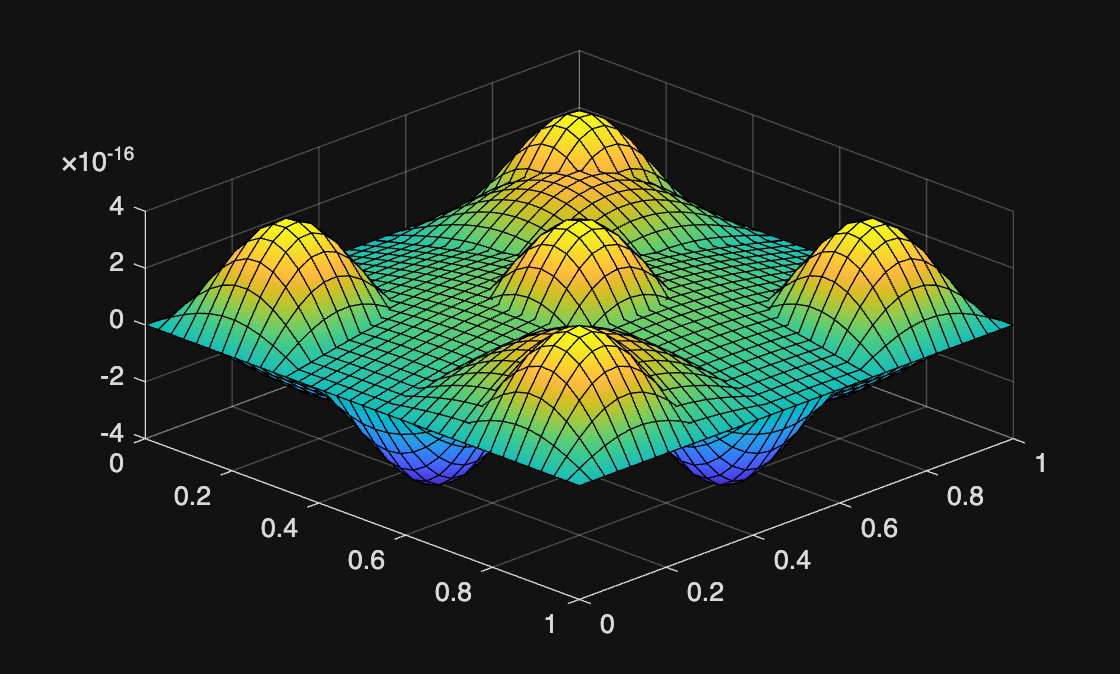

% Validation of Boundary Conditions
clf('reset')
hold on

% Plot of conditions Null conditions for Ux {x, y, z}
fsurf(@(x, y) ux(x, y, 0), [0 1 0 1])     % Condition for z = 0
fsurf(@(x, y) ux(x, y, 1), [0 1 0 1])     % Condition for z = 1
fsurf(@(x, z) ux(x, 0, z), [0 1 0 1])     % Condition for y = 0
fsurf(@(x, z) ux(x, 1, z), [0 1 0 1])     % Condition for y = 1
fsurf(@(y, z) ux(0, y, z), [0 1 0 1])     % Condition for x = 0
fsurf(@(y, z) ux(1, y, z), [0 1 0 1])     % Condition for x = 1

% Plot of conditions Null conditions for Uy {x, y, z}
fsurf(@(x, y) uy(x, y, 0), [0 1 0 1])     % Condition for z = 0
fsurf(@(x, y) uy(x, y, 1), [0 1 0 1])     % Condition for z = 1
fsurf(@(x, z) uy(x, 0, z), [0 1 0 1])     % Condition for y = 0
fsurf(@(x, z) uy(x, 1, z), [0 1 0 1])     % Condition for y = 1
fsurf(@(y, z) uy(0, y, z), [0 1 0 1])     % Condition for x = 0
fsurf(@(y, z) uy(1, y, z), [0 1 0 1])     % Condition for x = 1

% Plot of conditions Null conditions for Uz {x, y, z}
fsurf(@(x, y) uz(x, y, 0), [0 1 0 1])     % Condition for z = 0
fsurf(@(x, y) uz(x, y, 1), [0 1 0 1])     % Condition for z = 1
fsurf(@(x, z) uz(x, 0, z), [0 1 0 1])     % Condition for y = 0
fsurf(@(x, z) uz(x, 1, z), [0 1 0 1])     % Condition for y = 1
fsurf(@(y, z) uz(0, y, z), [0 1 0 1])     % Condition for x = 0
fsurf(@(y, z) uz(1, y, z), [0 1 0 1])     % Condition for x = 1

hold off
grid on
view([45, 45])

#### Definition of Cuadrature and Polynomial degrees

Now for the first definitions for the method, we must import the cuadrature that's going to be used, and the polynomial degree that's going to be used for the solution

% It's possible to change the values below to alter the polynomial and
% cuadrature precision for more general viewing
TablesQuadForm3d        % Importing of cuadrature for thetrahedron
TablesQuadForm          % Importing of cuadrature for triangles

k = 1;  % Polynomial Degree

% Switch case for the selection of formulas: cuadratures
switch k
    case 0 
        formulas={tetra3,tetra1,matrix0,matrix4};
    case 1
        formulas={tetra5,tetra3,matrix4,matrix9};
    case 2
        formulas={tetra7,tetra5,matrix9,matrix11};
    case 3
        formulas={tetra9,tetra7,matrix11,matrix14};
    case 4
        formulas={tetra9,tetra9,matrix14,matrix16};
end

% Reduction of weights: Sum of weights it's defined to be equal to 2, for
% normalization it's reduced to 1.
formulas{3}(:,4)=formulas{3}(:,4)/2;
formulas{4}(:,4)=formulas{4}(:,4)/2;

#### Norm of solutions for error definitions

The `errorElem `function it's used for this task, the idea used it's comparison with the origin that leaves the norm of elements $\mathit{\mathbf{u}}$and $\mathit{\mathbf{q}}$with known solution


$$|\mathit{\mathbf{p}}-{\mathit{\mathbf{p}}}^* |_{L^2 } \;=|\mathit{\mathbf{p}}|_{L^2 } \;:{\mathit{\mathbf{p}}}^* =0$$


% Error elements definition for display handle
ErrorU=[];
ErrorQ=[];
ErrorUhat=[];

ErrorPu=[];
ErrorPuhat=[];
ErrorUstar=[];
h=[];

% Norms of unknowns for relative error
Tmax=listT{end};                    % Listing of T elements
Nelts=size(Tmax.elements,1);        % Number of elements enlisted
d3=nchoosek(k+3,3);                 % d_i definition of set (cardinality)

% Computation of norm for U & G
normU = errorElem(Tmax,ux,zeros(d3,Nelts),k,formulas{1})...
      + errorElem(Tmax,uy,zeros(d3,Nelts),k,formulas{1})...
      + errorElem(Tmax,uz,zeros(d3,Nelts),k,formulas{1});

normG = errorElem(Tmax,gx,zeros(d3,Nelts),k,formulas{1})...
      + errorElem(Tmax,gy,zeros(d3,Nelts),k,formulas{1})...
      + errorElem(Tmax,gz,zeros(d3,Nelts),k,formulas{1});

#### HDG: The main iteration

Firstly the method it's created to run in a single run *(presence of one element only)*, with this in mind, when going to expand the idea must be iterated over the different structures

% Definition of the action of tau: Identity
tau = ones(4,Nelts);

% -------------------------------- HDG 3D main function --------------------------------------- %

% Definitions asociated with the tetrahedrization
d2 = nchoosek(k+2,2);    
d3 = nchoosek(k+3,3); 

block3 = @(x) (1+(x-1)*d3):(x*d3);

Nelts  = size(T.elements,1);
Nfaces = size(T.faces,1);
Ndir   = size(T.dirichlet,1);
Nneu   = size(T.neumann,1);

% 4th intervention
face = T.facebyele';                    % 4 x Nelts
face = (face(:)-1)*2*d2;                % First degree of freedom of each face by element                                               
face = bsxfun(@plus,face,1:2*d2);       % 4*Nelts x d2 (d.o.f. for each face)                                              
face = reshape(face',4*2*d2,Nelts);     % d.o.f. for the 4 faces of each element

[J,I] = meshgrid(1:4*2*d2);

R = face(I(:),:); R=reshape(R,4*2*d2,4*2*d2,Nelts);   % Mesh grid definition inside T_i element "Row-Axis"
C = face(J(:),:); C=reshape(C,4*2*d2,4*2*d2,Nelts);   % Mesh grid definition inside T_i element "Column-Axis"

% R_ij^K d.o.f. for local (i,j) d.o.f. in element K ; R_ij^K=C_ji^K
RowsRHS = reshape(face,4*2*d2*Nelts,1);            % Definition of solution shape   

% 4th intervention
% Dirichlet faces: defintion
dirfaces = (T.dirfaces(:)-1)*2*d2;          % First degree of freedom of each face by element
dirfaces = bsxfun(@plus,dirfaces,1:2*d2);   % Bitwise sum of dirfaces and 1:d2 > dirfaces + 1:d2
dirfaces = reshape(dirfaces',2*d2*Ndir,1);  % Reshape of dirfaces

% Reduced version of free
free = (1: 2*d2*Nfaces);

% Cleaning of dirfaces: Positions not needed
free(dirfaces) = [];      % Empty of dirfaces positions on free

% Neumann faces: defintion
neufaces = (T.neufaces(:)-1)*2*d2;          % First degree of freedom of each face by element
neufaces = bsxfun(@plus,neufaces,1:2*d2);   % Bitwise sum of neufaces and 1:d2 > neufaces + 1:d2
neufaces = reshape(neufaces',2*d2*Nneu,1);

**Normalization fo the normals: **From the structures we defined the normals as a proportion of the area, this definition was used in the past exploiding the advantages of the integrals corresponding to the products with the normals on the faces, now this idea must be changed in need to generalize the idea for the products involving tangential definitions of the functions.

% - First we need to obtain the informations in the normals per face
%   without afecting the order stablished
normals   = reshape(T.normals', [3, 4*Nelts])

normals =    -0.0132   -0.1146    0.0238    0.1040   -0.0483    0.0297    0.0837   -0.0650   -0.0396   -0.0357    0.1049   -0.0297    0.0510   -0.0374   -0.0471    0.0335    0.0659    0.0184   -0.1040    0.0197    0.0184   -0.0308   -0.1002    0.1126   -0.0652   -0.0186   -0.0164    0.1002    0.0291   -0.1089    0.0374    0.0424   -0.0565    0.0490   -0.0395    0.0471   -0.0635   -0.0316    0.0650    0.0301   -0.0648    0.0167    0.0952   -0.0471   -0.0176   -0.1211    0.1146    0.0241   -0.0758    0.0186
   -0.0483    0.0496   -0.0302    0.0289   -0.0132    0.1011    0.0228   -0.1107    0.0577    0.0190    0.0244   -0.1011    0.0145   -0.0957    0.1052   -0.0241   -0.0396    0.1107   -0.0289   -0.0422    0.0496    0.0329   -0.0386   -0.0439    0.0285    0.0493   -0.1165    0.0386   -0.0595   -0.0177    0.0957   -0.0185   -0.0758    0.0173    0.1037   -0.0452   -0.0121    0.0165    0.1107   -0.1152   -0.0529    0.0422   -0.0345    0.0452   -0.0645    0.0259   -0.0496    0.0882    0.056

% Now we normalize per face
normals   = normals ./ vecnorm(normals)

normals =    -0.1894   -0.8064    0.2496    0.9306   -0.6943    0.2710    0.9119   -0.4735   -0.4923   -0.3082    0.9148   -0.2710    0.6527   -0.3521   -0.3559    0.3233    0.7625    0.1541   -0.9306    0.1646    0.2404   -0.2996   -0.9031    0.8203   -0.7749   -0.1513   -0.1323    0.9031    0.3645   -0.9398    0.3521    0.3630   -0.5872    0.3955   -0.3478    0.3466   -0.6670   -0.3091    0.4735    0.2483   -0.7504    0.1411    0.8971   -0.3466   -0.1894   -0.9572    0.8064    0.2506   -0.7876    0.1513
   -0.6943    0.3490   -0.3166    0.2588   -0.1894    0.9236    0.2487   -0.8064    0.7179    0.1641    0.2125   -0.9236    0.1860   -0.9002    0.7952   -0.2324   -0.4575    0.9252   -0.2588   -0.3536    0.6496    0.3203   -0.3483   -0.3197    0.3387    0.4019   -0.9422    0.3483   -0.7450   -0.1531    0.9002   -0.1583   -0.7876    0.1393    0.9123   -0.3326   -0.1269    0.1619    0.8064   -0.9501   -0.6119    0.3576   -0.3251    0.3326   -0.6943    0.2046   -0.3490    0.9187    0.587

% Finally we recover the structure
T.normals = reshape(normals, [3*4, Nelts])'

T = struct with fields:
    coordinates: [45×3 double]
       elements: [100×4 double]
      dirichlet: [84×3 double]
        neumann: [0×3 double]
          faces: [242×4 double]
       dirfaces: [159 160 161 162 163 164 165 166 167 168 169 170 171 172 173 174 175 176 177 178 179 180 181 182 183 184 185 186 187 188 189 190 191 192 193 194 195 196 197 198 199 200 201 202 203 204 205 206 207 208 209 210 211 212 213 … ] (1×84 double)
       neufaces: [1×0 double]
      facebyele: [100×4 double]
    orientation: [100×4 double]
           perm: [100×4 double]
         volume: [100×1 double]
           area: [242×1 double]
        normals: [100×12 double]
              A: [2×3×242 double]


### Construction of integral matrices

#### Volume matrices

For instance we need to consider the product corresponding to: $\langle \;u_h ,v_h \;\rangle_K$ and $\langle \;z_h ,r_h \;\rangle_K$ for this computation we need to obtain the integrals corresponding to the products of the basis $P\left(x\right)\cdot P\left(x\right)$

% First we locally define the variables:
formula = formulas{1};    % Quadrature 3D Integrals
Nnodes = size(formula,1); % Number of nodes in the formula

% Definition of normalized coordinates
xhat=formula(:,2);
yhat=formula(:,3);
zhat=formula(:,4);

% Evaluation on the reference element
[P, Px, Py, Pz] = dubiner3d(2*xhat-1,2*yhat-1,2*zhat-1,k);  % Nnd x d3

% Rescaling: Inner derivative: \hat{P}(x) := \check{P}(2 \cdot x - 1)
Px = 2*Px; Py = 2*Py; Pz = 2*Pz;

% Dubiner basis direct product with weights
wP= formula(:,5) .* P;

% Calculation of integral in reference element
Mi_reference = wP' * P

Mi_reference =     1.0000    0.0000    0.0000    0.0000
    0.0000    0.1000   -0.0000   -0.0000
    0.0000         0    0.3000    0.0000
    0.0000   -0.0000    0.0000    0.6000


% Integral for the first element of the structure
Mi_first_elem = T.volume(1) * wP' * P

Mi_first_elem =     0.0017    0.0000    0.0000    0.0000
    0.0000    0.0002   -0.0000   -0.0000
    0.0000         0    0.0005   -0.0000
    0.0000   -0.0000   -0.0000    0.0010


If we consider now the product of this form with the volume of each tetrahedron, we now can approximate all the mass integrals on the volume.

% Definition of product and generalization to all elements
Mi = kron(T.volume', wP' * P)

Mi =     0.0110   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0107   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0135   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0116   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0143   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0000    0.0011    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0011    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0014    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0012    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0014    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    

% Reshaping of the output Rotational Matrices
Mi = reshape(Mi, [d3, d3, Nelts])

Mi = Mi(:,:,1) =

    0.0110   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0000    0.0011    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0033   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
   -0.0000    0.0000   -0.0000    0.0066   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.0000    0.0000   -0.0000   -0.0000    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0005    0.0000    0.0000   -0.0000    0.0000
   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0008    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0016   -0.0000    0.0000
   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0024    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   

Now we might consider approximating the integral corresponding to the product: $\langle \;z_h ,\nabla \times r_h \;\rangle_K$ this envolves the integrals with $\partial_{\hat{\star} } P\left(x\right)\cdot P\left(x\right)$, this process is done using:

% Elements definition of the Piola transform : *^T
x12=T.coordinates(T.elements(:,2),1)-T.coordinates(T.elements(:,1),1); %x2-x1
x13=T.coordinates(T.elements(:,3),1)-T.coordinates(T.elements(:,1),1); %x3-x1
x14=T.coordinates(T.elements(:,4),1)-T.coordinates(T.elements(:,1),1); %x4-x1
y12=T.coordinates(T.elements(:,2),2)-T.coordinates(T.elements(:,1),2); %y2-y1
y13=T.coordinates(T.elements(:,3),2)-T.coordinates(T.elements(:,1),2); %y3-y1
y14=T.coordinates(T.elements(:,4),2)-T.coordinates(T.elements(:,1),2); %y4-y1
z12=T.coordinates(T.elements(:,2),3)-T.coordinates(T.elements(:,1),3); %z2-z1
z13=T.coordinates(T.elements(:,3),3)-T.coordinates(T.elements(:,1),3); %z3-z1
z14=T.coordinates(T.elements(:,4),3)-T.coordinates(T.elements(:,1),3); %z4-z1

% Matrix elements
axx=y13.*z14-y14.*z13;
axy=y14.*z12-y12.*z14;
axz=y12.*z13-y13.*z12;  %                   | a_xx  a_xy  a_xz |
ayx=x14.*z13-x13.*z14;  % \det{B} B^{-T} := | a_yx  a_yy  a_yz |
ayy=x12.*z14-x14.*z12;  %                   | a_zx  a_zy  a_zz |
ayz=x13.*z12-x12.*z13;          
azx=x13.*y14-x14.*y13;
azy=x14.*y12-x12.*y14;
azz=x12.*y13-x13.*y12;

% Approximation on the reference element
CMx_hat = 1/6 * wP'*Px;
CMy_hat = 1/6 * wP'*Py;
CMz_hat = 1/6 * wP'*Pz;

% Computation of the Derivatives for the first element
CMx_first_elem = axx(1) * CMx_hat + axy(1) * CMy_hat + axz(1) * CMz_hat

CMx_first_elem =          0    0.0267    0.1190    0.0176    0.0213    0.0134    0.0134   -0.0360    0.0595   -0.0110
         0   -0.0000   -0.0000   -0.0000    0.0080    0.0195    0.0026    0.0000   -0.0000    0.0000
         0   -0.0000   -0.0000   -0.0000   -0.0043    0.0134   -0.0000    0.0799    0.0079    0.0000
         0   -0.0000   -0.0000   -0.0000   -0.0043   -0.0027    0.0241    0.0072    0.1071    0.0198
         0    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
         0    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
         0   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    

Using this definition we can construct the products per derivative for all elements

% Definition of Products for all elements
CMx = kron(axx', CMx_hat) + kron(axy', CMy_hat) + kron(axz', CMz_hat)

CMx =          0    0.0267    0.1190    0.0176    0.0213    0.0134    0.0134   -0.0360    0.0595   -0.0110         0   -0.0496   -0.0135    0.0645    0.0031   -0.0248   -0.0248    0.0179   -0.0068   -0.0403         0   -0.0449    0.0489    0.0527    0.0125   -0.0224   -0.0224   -0.0053    0.0245   -0.0330         0    0.0269    0.0204   -0.0680   -0.0023    0.0134    0.0134   -0.0210    0.0102    0.0425         0    0.0412   -0.0404   -0.0879   -0.0141    0.0206    0.0206   -0.0048   -0.0202    0.0549
         0   -0.0000   -0.0000   -0.0000    0.0080    0.0195    0.0026    0.0000   -0.0000    0.0000         0    0.0000    0.0000   -0.0000   -0.0149   -0.0033    0.0097   -0.0000    0.0000    0.0000         0    0.0000   -0.0000   -0.0000   -0.0135    0.0073    0.0079    0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0081    0.0045   -0.0102    0.0000   -0.0000   -0.0000         0   -0.0000    0.0000    0.0000    0.0124   -0.0053   -0.0132    0.0000    0.0000   

CMy = kron(ayx', CMx_hat) + kron(ayy', CMy_hat) + kron(ayz', CMz_hat);
CMz = kron(azx', CMx_hat) + kron(azy', CMy_hat) + kron(azz', CMz_hat);

% Reshape on 3D for construction
CMx = reshape(CMx, [d3, d3, Nelts])

CMx = CMx(:,:,1) =

         0    0.0267    0.1190    0.0176    0.0213    0.0134    0.0134   -0.0360    0.0595   -0.0110
         0   -0.0000   -0.0000   -0.0000    0.0080    0.0195    0.0026    0.0000   -0.0000    0.0000
         0   -0.0000   -0.0000   -0.0000   -0.0043    0.0134   -0.0000    0.0799    0.0079    0.0000
         0   -0.0000   -0.0000   -0.0000   -0.0043   -0.0027    0.0241    0.0072    0.1071    0.0198
         0    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
         0    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
         0   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000 

CMy = reshape(CMy, [d3, d3, Nelts]);
CMz = reshape(CMz, [d3, d3, Nelts]);

#### Face matrices

Now we are focusing on the face integrals, almost all of this integrals are new on the scheme, because of this it's important to have an attention to detail for this construction. For instance the first kind of integrals we're going to center our efforts it's the form $\tau \;\langle \;u_h^t \;,\nu_h \;\rangle_{\partial K}$, this involves the the operation $P\left(x\right)\cdot P\left(x\right)$ on the faces.

% First we're going to define the auxiliar variables for this contruction
formula = formulas{4};
Nelts   = size(T.elements,1);
Nnodes  = size(formula,1);

d2=nchoosek(k+2,2);   
d3=nchoosek(k+3,3); 

% Definition of the element area * Evaluation of Tau coeficients
Area    = T.area(T.facebyele)'; % 4 x Nelts
TauArea = Area.*tau;            % 4 x Nelts
T.perm  = T.perm';              % 4 x Nelts

% Definition on the reference element 
s=formula(:,2);         % Reference "X-Axis"
t=formula(:,3);         % Reference "Y-Axis"
weights=formula(:,4);   % Weights of formulas

Due to the nature of the faces, to describe each and every face on the system using the reference element we need to use different combinations on the basis. For instance we can see the behaviour of the element and their faces and normals.

% Element level selection
level = 10;

% Coordinates of the elements
coordinates_element = T.coordinates(T.elements(level, :), :);

% Coordinates components for the element
x = coordinates_element(:, 1);
y = coordinates_element(:, 2);
z = coordinates_element(:, 3);

% Normals decomposition for the element
x_normal = T.normals(level, 1:3:3*4);
y_normal = T.normals(level, 2:3:3*4);
z_normal = T.normals(level, 3:3:3*4);

% Definition of normals per face
normal_1 = T.normals(level, 3*0 + 1:3);
normal_2 = T.normals(level, 3*1 + 1:3*2);
normal_3 = T.normals(level, 3*2 + 1:3*3);
normal_4 = T.normals(level, 3*3 + 1:3*4);

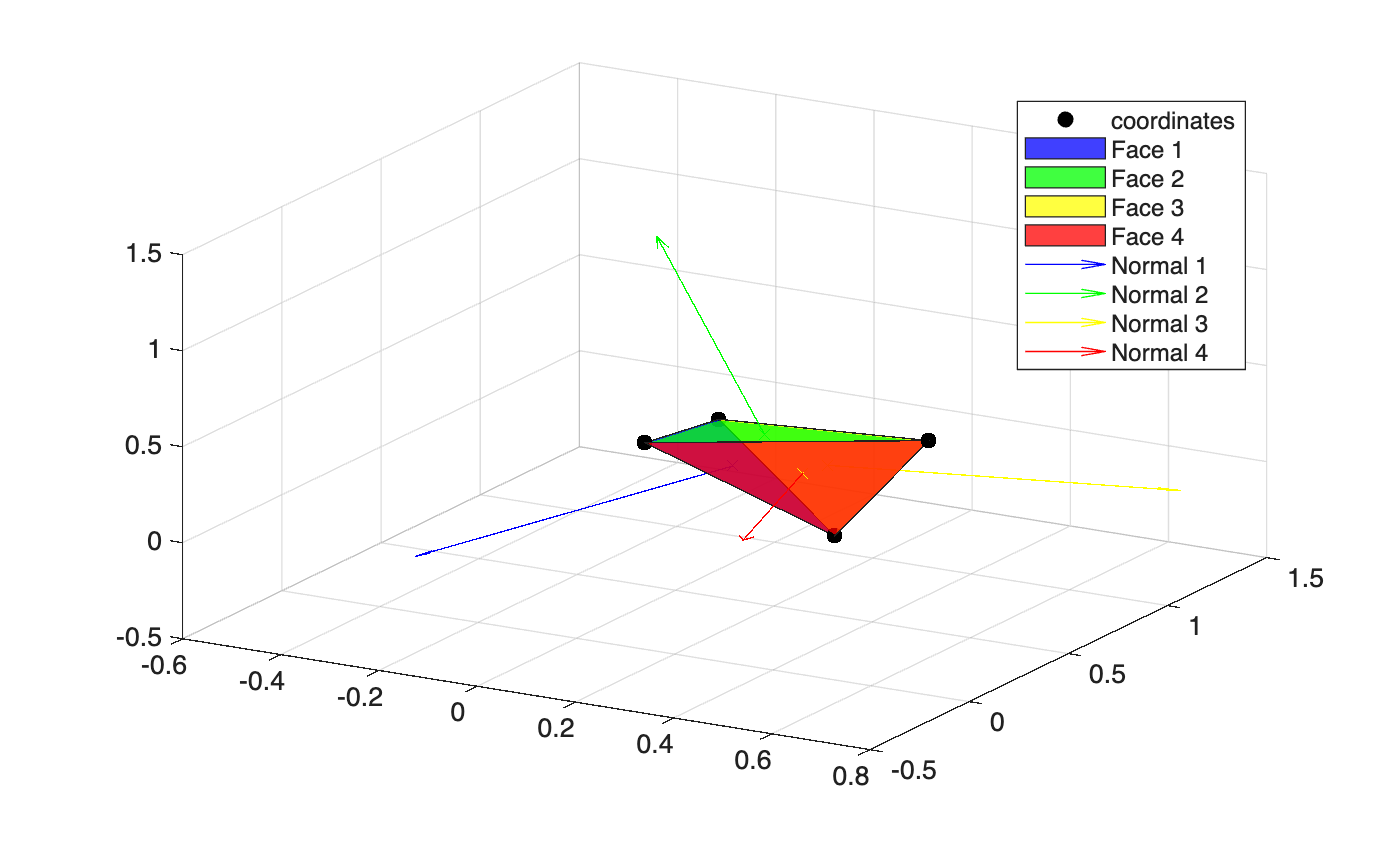

% Scatter of the marks for the coordinates
clf('reset')
hold on

% Vertices Scatter: Draw of nodes
scatter3(x, y, z, 'filled', 'k', DisplayName='coordinates')

% Edges definitions
plot3(x([1, 2]), y([1, 2]), z([1, 2]), '-.k', handleVisibility='off')
plot3(x([1, 3]), y([1, 3]), z([1, 3]), '-.k', handleVisibility='off')
plot3(x([1, 4]), y([1, 4]), z([1, 4]), '-.k', handleVisibility='off')

plot3(x([2, 3]), y([2, 3]), z([2, 3]), '-.k', handleVisibility='off')
plot3(x([2, 4]), y([2, 4]), z([2, 4]), '-.k', handleVisibility='off')

plot3(x([3, 4]), y([3, 4]), z([3, 4]), '-.k', handleVisibility='off')

% Faces patching: Order of face
fill3(x([1, 2, 3]), y([1, 2, 3]), z([1, 2, 3]), 'b', ...
                                 FaceAlpha=.75, DisplayName='Face 1')
fill3(x([1, 2, 4]), y([1, 2, 4]), z([1, 2, 4]), 'g', ...
                                 FaceAlpha=.75, DisplayName='Face 2')
fill3(x([1, 3, 4]), y([1, 3, 4]), z([1, 3, 4]), 'y', ...
                                 FaceAlpha=.75, DisplayName='Face 3')
fill3(x([4, 2, 3]), y([4, 2, 3]), z([4, 2, 3]), 'r', ...
                                 FaceAlpha=.75, DisplayName='Face 4')

% Position of arrows and normals on the face
plot3(mean(x([1, 2, 3])), mean(y([1, 2, 3])), mean(z([1, 2, 3])), ...
      'xb', handleVisibility='off')
quiver3(mean(x([1, 2, 3])), mean(y([1, 2, 3])), mean(z([1, 2, 3])), ...
        x_normal(1), y_normal(1), z_normal(1), 'b', DisplayName='Normal 1')

plot3(mean(x([1, 2, 4])), mean(y([1, 2, 4])), mean(z([1, 2, 4])), ...
      'xg', handleVisibility='off')
quiver3(mean(x([1, 2, 4])), mean(y([1, 2, 4])), mean(z([1, 2, 4])), ...
        x_normal(2), y_normal(2), z_normal(2), 'g', DisplayName='Normal 2')

plot3(mean(x([1, 3, 4])), mean(y([1, 3, 4])), mean(z([1, 3, 4])), ...
      'xy', handleVisibility='off')
quiver3(mean(x([1, 3, 4])), mean(y([1, 3, 4])), mean(z([1, 3, 4])), ...
        x_normal(3), y_normal(3), z_normal(3), 'y', DisplayName='Normal 3')

plot3(mean(x([4, 2, 3])), mean(y([4, 2, 3])), mean(z([4, 2, 3])), ...
      'xy', handleVisibility='off')
quiver3(mean(x([4, 2, 3])), mean(y([4, 2, 3])), mean(z([4, 2, 3])), ...
        x_normal(4), y_normal(4), z_normal(4), 'r', DisplayName='Normal 4')

legend(location='best')
view([30, 30])
grid on
hold off

For examination pourpuses we can validate if for instance each an every one of the normals are correctly defined:

% Validation of products
% - Face 1
% Using the surface definition from before, we can define it's normal by:
generator_1 = coordinates_element(2, :) - coordinates_element(1, :);
generator_2 = coordinates_element(3, :) - coordinates_element(1, :);
disp('Products of face 1:')

Products of face 1:


+ generator_1 * normal_1', generator_2 * normal_1'

ans = 0

ans = 0

% - Face 2
% Using the surface definition from before, we can define it's normal by:
generator_1 = coordinates_element(2, :) - coordinates_element(1, :);
generator_2 = coordinates_element(4, :) - coordinates_element(1, :);
disp('Products of face 1:')

Products of face 1:


generator_1 * normal_2', generator_2 * normal_2'

ans = 6.9389e-18

ans = 0

% - Face 3
% Using the surface definition from before, we can define it's normal by:
generator_1 = coordinates_element(3, :) - coordinates_element(1, :);
generator_2 = coordinates_element(4, :) - coordinates_element(1, :);
disp('Products of face 1:')

Products of face 1:


generator_1 * normal_3', generator_2 * normal_3'

ans = -5.5511e-17

ans = 0

% - Face 4
% Using the surface definition from before, we can define it's normal by:
generator_1 = coordinates_element(2, :) - coordinates_element(4, :);
generator_2 = coordinates_element(3, :) - coordinates_element(4, :);
disp('Products of face 1:')

Products of face 1:


generator_1 * normal_4', generator_2 * normal_4'

ans = 0

ans = -6.9389e-18

Now a vital part of this process it's validate if the surfaces are correctly oriented, for instance we will consider the orientation with normals going outwards the tetrahedron, consider:

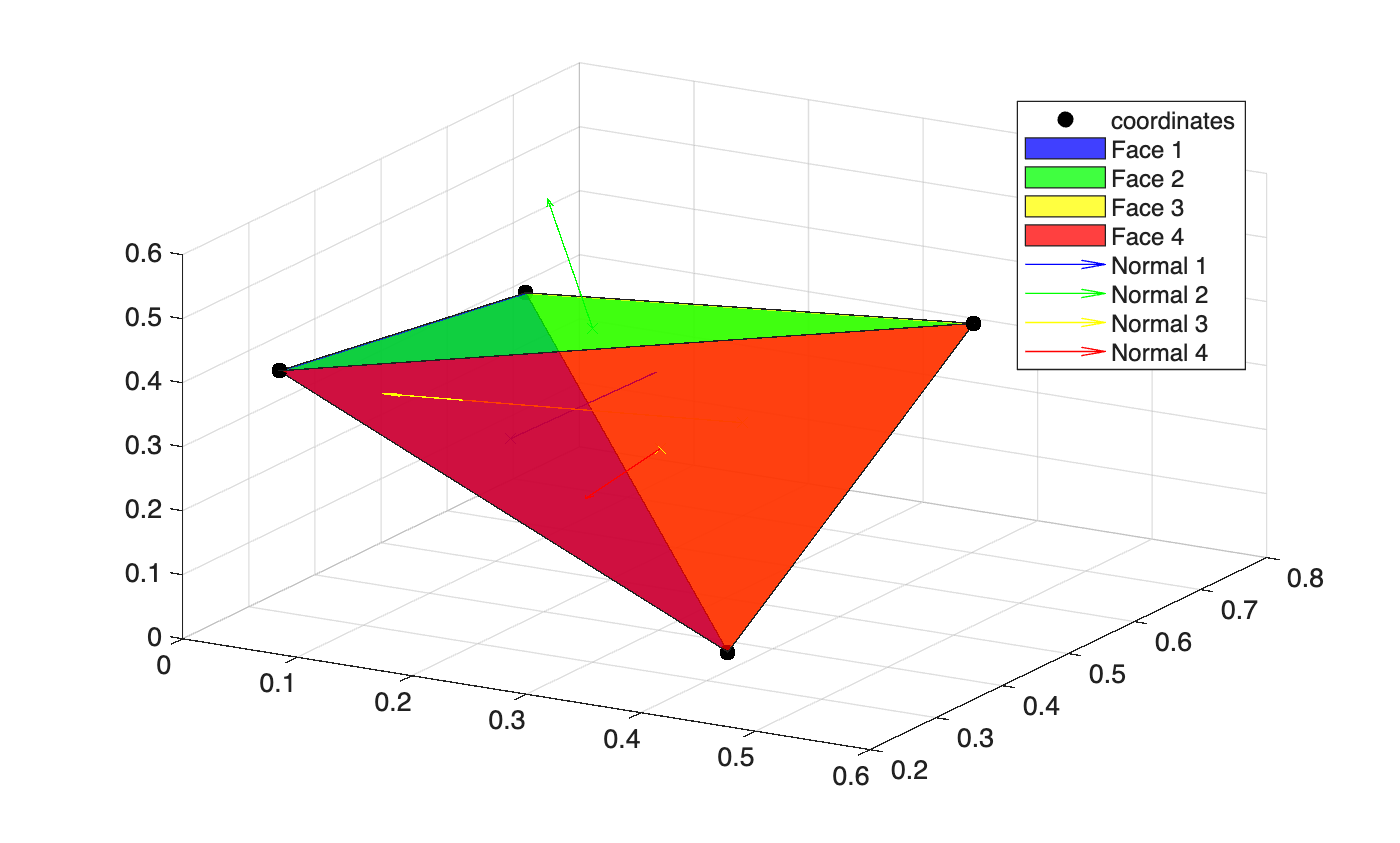

% Scatter of the marks for the coordinates
clf('reset')
hold on

% Vertices Scatter: Draw of nodes
scatter3(x, y, z, 'filled', 'k', DisplayName='coordinates')

% Edges definitions
plot3(x([1, 2]), y([1, 2]), z([1, 2]), '-.k', handleVisibility='off')
plot3(x([1, 3]), y([1, 3]), z([1, 3]), '-.k', handleVisibility='off')
plot3(x([1, 4]), y([1, 4]), z([1, 4]), '-.k', handleVisibility='off')

plot3(x([2, 3]), y([2, 3]), z([2, 3]), '-.k', handleVisibility='off')
plot3(x([2, 4]), y([2, 4]), z([2, 4]), '-.k', handleVisibility='off')

plot3(x([3, 4]), y([3, 4]), z([3, 4]), '-.k', handleVisibility='off')

% Faces patching: Order of face
fill3(x([1, 2, 3]), y([1, 2, 3]), z([1, 2, 3]), 'b', ...
                                 FaceAlpha=.75, DisplayName='Face 1')
fill3(x([1, 2, 4]), y([1, 2, 4]), z([1, 2, 4]), 'g', ...
                                 FaceAlpha=.75, DisplayName='Face 2')
fill3(x([1, 3, 4]), y([1, 3, 4]), z([1, 3, 4]), 'y', ...
                                 FaceAlpha=.75, DisplayName='Face 3')
fill3(x([4, 2, 3]), y([4, 2, 3]), z([4, 2, 3]), 'r', ...
                                 FaceAlpha=.75, DisplayName='Face 4')

% Directors of faces
F1_directors = [x(2) - x(1), y(2) - y(1), z(2) - z(1); ...
                x(3) - x(1), y(3) - y(1), z(3) - z(1)];
F2_directors = [x(2) - x(1), y(2) - y(1), z(2) - z(1); ...
                x(4) - x(1), y(4) - y(1), z(4) - z(1)];
F3_directors = [x(3) - x(1), y(3) - y(1), z(3) - z(1); ...
                x(4) - x(1), y(4) - y(1), z(4) - z(1)];
F4_directors = [x(2) - x(4), y(2) - y(4), z(2) - z(4); ...
                x(3) - x(4), y(3) - y(4), z(3) - z(4)];

% Normals to the surfaces
F1_normal = [F1_directors(1, 2)*F1_directors(2, 3) - F1_directors(1, 3)*F1_directors(2, 2), ...
             F1_directors(1, 3)*F1_directors(2, 1) - F1_directors(1, 1)*F1_directors(2, 3), ...
             F1_directors(1, 1)*F1_directors(2, 2) - F1_directors(1, 2)*F1_directors(2, 1)];
F2_normal = [F2_directors(1, 2)*F2_directors(2, 3) - F2_directors(1, 3)*F2_directors(2, 2), ...
             F2_directors(1, 3)*F2_directors(2, 1) - F2_directors(1, 1)*F2_directors(2, 3), ...
             F2_directors(1, 1)*F2_directors(2, 2) - F2_directors(1, 2)*F2_directors(2, 1)];
F3_normal = [F3_directors(1, 2)*F3_directors(2, 3) - F3_directors(1, 3)*F3_directors(2, 2), ...
             F3_directors(1, 3)*F3_directors(2, 1) - F3_directors(1, 1)*F3_directors(2, 3), ...
             F3_directors(1, 1)*F3_directors(2, 2) - F3_directors(1, 2)*F3_directors(2, 1)];
F4_normal = [F4_directors(1, 2)*F4_directors(2, 3) - F4_directors(1, 3)*F4_directors(2, 2), ...
             F4_directors(1, 3)*F4_directors(2, 1) - F4_directors(1, 1)*F4_directors(2, 3), ...
             F4_directors(1, 1)*F4_directors(2, 2) - F4_directors(1, 2)*F4_directors(2, 1)];

% Position of arrows and orientations of faces
plot3(mean(x([1, 2, 3])), mean(y([1, 2, 3])), mean(z([1, 2, 3])), ...
      'xb', handleVisibility='off')
quiver3(mean(x([1, 2, 3])), mean(y([1, 2, 3])), mean(z([1, 2, 3])), ...
        F1_normal(1), F1_normal(2), F1_normal(3), 'b', DisplayName='Normal 1')

plot3(mean(x([1, 2, 4])), mean(y([1, 2, 4])), mean(z([1, 2, 4])), ...
      'xg', handleVisibility='off')
quiver3(mean(x([1, 2, 4])), mean(y([1, 2, 4])), mean(z([1, 2, 4])), ...
        F2_normal(1), F2_normal(2), F2_normal(3), 'g', DisplayName='Normal 2')

plot3(mean(x([1, 3, 4])), mean(y([1, 3, 4])), mean(z([1, 3, 4])), ...
      'xy', handleVisibility='off')
quiver3(mean(x([1, 3, 4])), mean(y([1, 3, 4])), mean(z([1, 3, 4])), ...
        F3_normal(2), F3_normal(2), F3_normal(3), 'y', DisplayName='Normal 3')

plot3(mean(x([4, 2, 3])), mean(y([4, 2, 3])), mean(z([4, 2, 3])), ...
      'xy', handleVisibility='off')
quiver3(mean(x([4, 2, 3])), mean(y([4, 2, 3])), mean(z([4, 2, 3])), ...
        F4_normal(1), F4_normal(2), F4_normal(3), 'r', DisplayName='Normal 4')

legend(location='best')
view([30, 30])
grid on
hold off

This shows us that the orientation in the the paper it's inverted for faces 1 and 3, for instance we need to consider to change this orientation using:

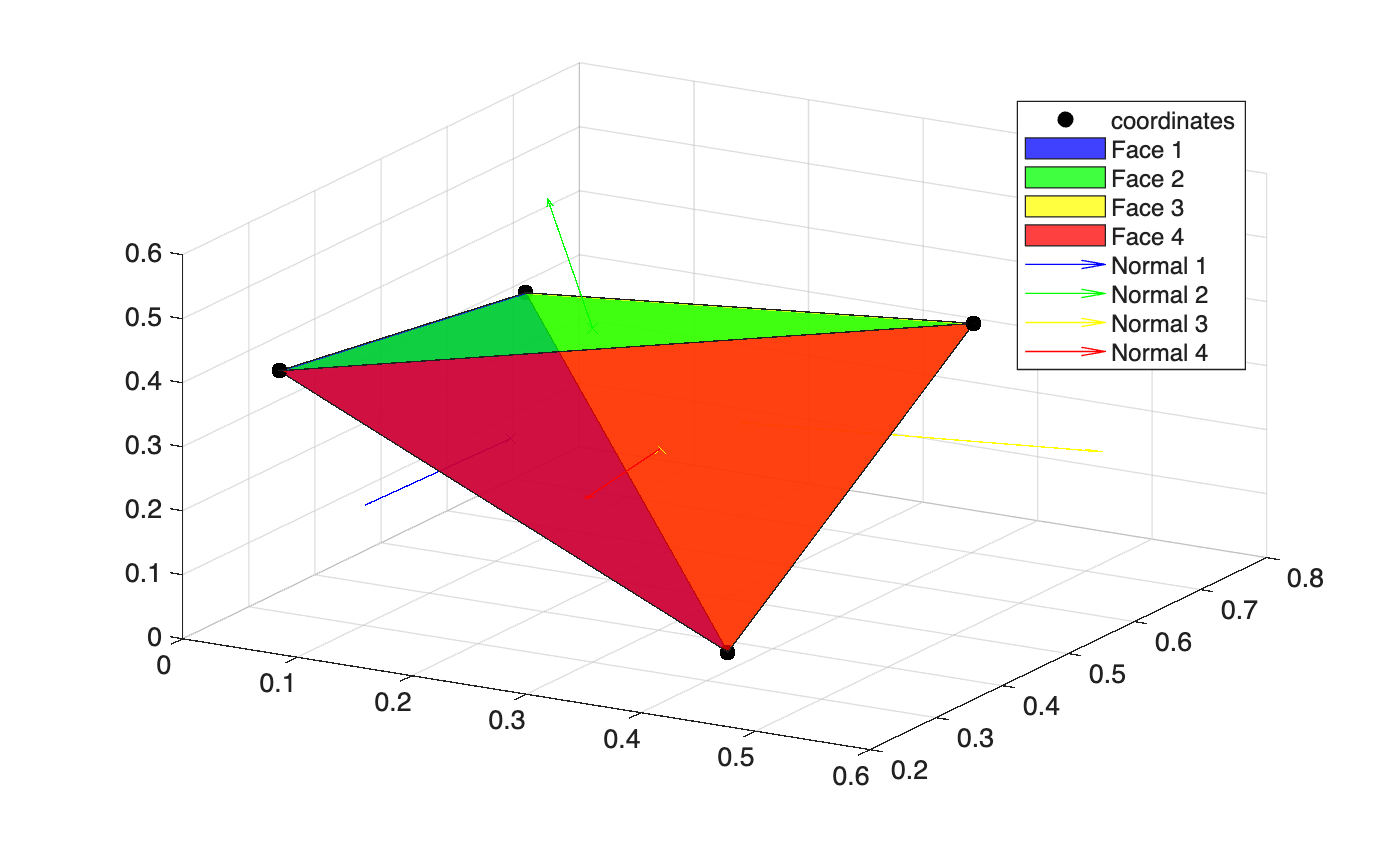

% Scatter of the marks for the coordinates
clf('reset')
hold on

% Vertices Scatter: Draw of nodes
scatter3(x, y, z, 'filled', 'k', DisplayName='coordinates')

% Edges definitions
plot3(x([1, 2]), y([1, 2]), z([1, 2]), '-.k', handleVisibility='off')
plot3(x([1, 3]), y([1, 3]), z([1, 3]), '-.k', handleVisibility='off')
plot3(x([1, 4]), y([1, 4]), z([1, 4]), '-.k', handleVisibility='off')

plot3(x([2, 3]), y([2, 3]), z([2, 3]), '-.k', handleVisibility='off')
plot3(x([2, 4]), y([2, 4]), z([2, 4]), '-.k', handleVisibility='off')

plot3(x([3, 4]), y([3, 4]), z([3, 4]), '-.k', handleVisibility='off')

% Faces patching: Order of face
fill3(x([1, 3, 2]), y([1, 3, 2]), z([1, 3, 2]), 'b', ...
                                 FaceAlpha=.75, DisplayName='Face 1')
fill3(x([1, 2, 4]), y([1, 2, 4]), z([1, 2, 4]), 'g', ...
                                 FaceAlpha=.75, DisplayName='Face 2')
fill3(x([1, 4, 3]), y([1, 4, 3]), z([1, 4, 3]), 'y', ...
                                 FaceAlpha=.75, DisplayName='Face 3')
fill3(x([4, 2, 3]), y([4, 2, 3]), z([4, 2, 3]), 'r', ...
                                 FaceAlpha=.75, DisplayName='Face 4')

% Directors of faces: Changes on F1 -> [1 3 2] and F3 -> [1 4 3]
F1_directors = [x(3) - x(1), y(3) - y(1), z(3) - z(1); ...
                x(2) - x(1), y(2) - y(1), z(2) - z(1)];
F2_directors = [x(2) - x(1), y(2) - y(1), z(2) - z(1); ...
                x(4) - x(1), y(4) - y(1), z(4) - z(1)];
F3_directors = [x(4) - x(1), y(4) - y(1), z(4) - z(1); ...
                x(3) - x(1), y(3) - y(1), z(3) - z(1)];
F4_directors = [x(2) - x(4), y(2) - y(4), z(2) - z(4); ...
                x(3) - x(4), y(3) - y(4), z(3) - z(4)];

% Normals to the surfaces
F1_normal = [F1_directors(1, 2)*F1_directors(2, 3) - F1_directors(1, 3)*F1_directors(2, 2), ...
             F1_directors(1, 3)*F1_directors(2, 1) - F1_directors(1, 1)*F1_directors(2, 3), ...
             F1_directors(1, 1)*F1_directors(2, 2) - F1_directors(1, 2)*F1_directors(2, 1)];
F2_normal = [F2_directors(1, 2)*F2_directors(2, 3) - F2_directors(1, 3)*F2_directors(2, 2), ...
             F2_directors(1, 3)*F2_directors(2, 1) - F2_directors(1, 1)*F2_directors(2, 3), ...
             F2_directors(1, 1)*F2_directors(2, 2) - F2_directors(1, 2)*F2_directors(2, 1)];
F3_normal = [F3_directors(1, 2)*F3_directors(2, 3) - F3_directors(1, 3)*F3_directors(2, 2), ...
             F3_directors(1, 3)*F3_directors(2, 1) - F3_directors(1, 1)*F3_directors(2, 3), ...
             F3_directors(1, 1)*F3_directors(2, 2) - F3_directors(1, 2)*F3_directors(2, 1)];
F4_normal = [F4_directors(1, 2)*F4_directors(2, 3) - F4_directors(1, 3)*F4_directors(2, 2), ...
             F4_directors(1, 3)*F4_directors(2, 1) - F4_directors(1, 1)*F4_directors(2, 3), ...
             F4_directors(1, 1)*F4_directors(2, 2) - F4_directors(1, 2)*F4_directors(2, 1)];

% Position of arrows and orientations of faces
plot3(mean(x([1, 2, 3])), mean(y([1, 2, 3])), mean(z([1, 2, 3])), ...
      'xb', handleVisibility='off')
quiver3(mean(x([1, 2, 3])), mean(y([1, 2, 3])), mean(z([1, 2, 3])), ...
        F1_normal(1), F1_normal(2), F1_normal(3), 'b', DisplayName='Normal 1')

plot3(mean(x([1, 2, 4])), mean(y([1, 2, 4])), mean(z([1, 2, 4])), ...
      'xg', handleVisibility='off')
quiver3(mean(x([1, 2, 4])), mean(y([1, 2, 4])), mean(z([1, 2, 4])), ...
        F2_normal(1), F2_normal(2), F2_normal(3), 'g', DisplayName='Normal 2')

plot3(mean(x([1, 3, 4])), mean(y([1, 3, 4])), mean(z([1, 3, 4])), ...
      'xy', handleVisibility='off')
quiver3(mean(x([1, 3, 4])), mean(y([1, 3, 4])), mean(z([1, 3, 4])), ...
        F3_normal(2), F3_normal(2), F3_normal(3), 'y', DisplayName='Normal 3')

plot3(mean(x([4, 2, 3])), mean(y([4, 2, 3])), mean(z([4, 2, 3])), ...
      'xy', handleVisibility='off')
quiver3(mean(x([4, 2, 3])), mean(y([4, 2, 3])), mean(z([4, 2, 3])), ...
        F4_normal(1), F4_normal(2), F4_normal(3), 'r', DisplayName='Normal 4')

legend(location='best')
view([30, 30])
grid on
hold off

Now that we know our structure it's well defined, we can now compute for instance for the first element that we review before:

% Computation of every possible combination for each face
O=zeros(size(s));       % Compatible Zero Matrix

points3d=[t,s,O;...     % Face 1
          s,O,t;...     % Face 2
          O,t,s;...     % Face 3
          s,t,1-s-t];   % Face 4

% Evaluation of the quadrature points on face K_hat
pb=dubiner3d(2*points3d(:,1)-1, ...  % Evaluation on quadrature points
             2*points3d(:,2)-1, ...  % of the Dubiner basis.
             2*points3d(:,3)-1, k);  % (4 * Nnodes) x d3

% Now we are going to make a direct product with the weights, but
% considering 4 possible combinations we need to repeat the weights for
% each one
pbweights = repmat(weights,4, 1) .* pb;

% Now for each face we're computing the product
pbpb = zeros(d3, d3, 4);    % Storage reservation: 3D definition per face

% Fill by face
pbpb(:, :, 1) = pbweights(0*Nnodes + 1:1*Nnodes, :)' * pb(0*Nnodes + 1:1*Nnodes, :);
pbpb(:, :, 2) = pbweights(1*Nnodes + 1:2*Nnodes, :)' * pb(1*Nnodes + 1:2*Nnodes, :);
pbpb(:, :, 3) = pbweights(1*Nnodes + 1:3*Nnodes, :)' * pb(1*Nnodes + 1:3*Nnodes, :);
pbpb(:, :, 4) = pbweights(3*Nnodes + 1:4*Nnodes, :)' * pb(3*Nnodes + 1:4*Nnodes, :);

% Storage variables
tauPP = zeros([3*d3, 3*d3]);
nPP   = zeros([3*d3, 3*d3]);

% Computation of integral per face
for l = 1:4

    % Matrix computation per face
    Ntan = [y_normal(l)^2 + z_normal(l)^2,      -x_normal(l)*y_normal(l),       -x_normal(l)*z_normal(l); ...
                 -y_normal(l)*x_normal(l), x_normal(l)^2 + y_normal(l)^2,       -y_normal(l)*z_normal(l); ...
                 -z_normal(l)*x_normal(l),      -z_normal(l)*y_normal(l), x_normal(l)^2 + y_normal(l)^2];

    tauPP_l = TauArea(l, level) * kron(Ntan, pbpb(:, :, l));

    % Storage on boundary integral
    tauPP = tauPP +  tauPP_l;
end

% This is the Matrix we wanted, now we need to consider the computation to
% all elements
tauPP

tauPP =     0.4720    0.0024   -0.0592    0.0868    0.0367    0.0012    0.0012    0.1361   -0.0296    0.1227   -0.0792    0.0270    0.0236   -0.0157   -0.0040    0.0135    0.0135   -0.0276    0.0118   -0.0199    0.0233   -0.0096   -0.0293    0.0700    0.0029   -0.0048   -0.0048    0.0292   -0.0146   -0.0350
    0.0024    0.0787   -0.0000   -0.0000    0.0007   -0.0192    0.0052    0.0000    0.0000    0.0000    0.0270   -0.0132    0.0000   -0.0000    0.0081    0.0055   -0.0010   -0.0000   -0.0000   -0.0000   -0.0096    0.0039   -0.0000    0.0000   -0.0029   -0.0064    0.0101    0.0000    0.0000    0.0000
   -0.0592   -0.0000    0.2360   -0.0000   -0.0073    0.0012    0.0000   -0.0208    0.0155    0.0000    0.0236    0.0000   -0.0396    0.0000    0.0008    0.0135   -0.0000    0.0126   -0.0031   -0.0000   -0.0293   -0.0000    0.0117   -0.0000   -0.0006   -0.0048    0.0000   -0.0164    0.0303    0.0000
    0.0868   -0.0000   -0.0000    0.4720   -0.0073   -0.0002    0.0022   -0.0272   -0.053

Now if we want to replicate this process for all the elements, we need to change some small definitions before any application, for instance now we're interested on the computation of the integrals on faces involving a mixed calculation of the basis $P\left(x\right)\cdot D\left(x\right)$ consider the integral: $\langle \;{\widehat{u} }_h^t \;,r\times n\rangle_{\partial K}$, for this case we need to validate that the faces are correctly oriented in each case, using the process before, we can define:

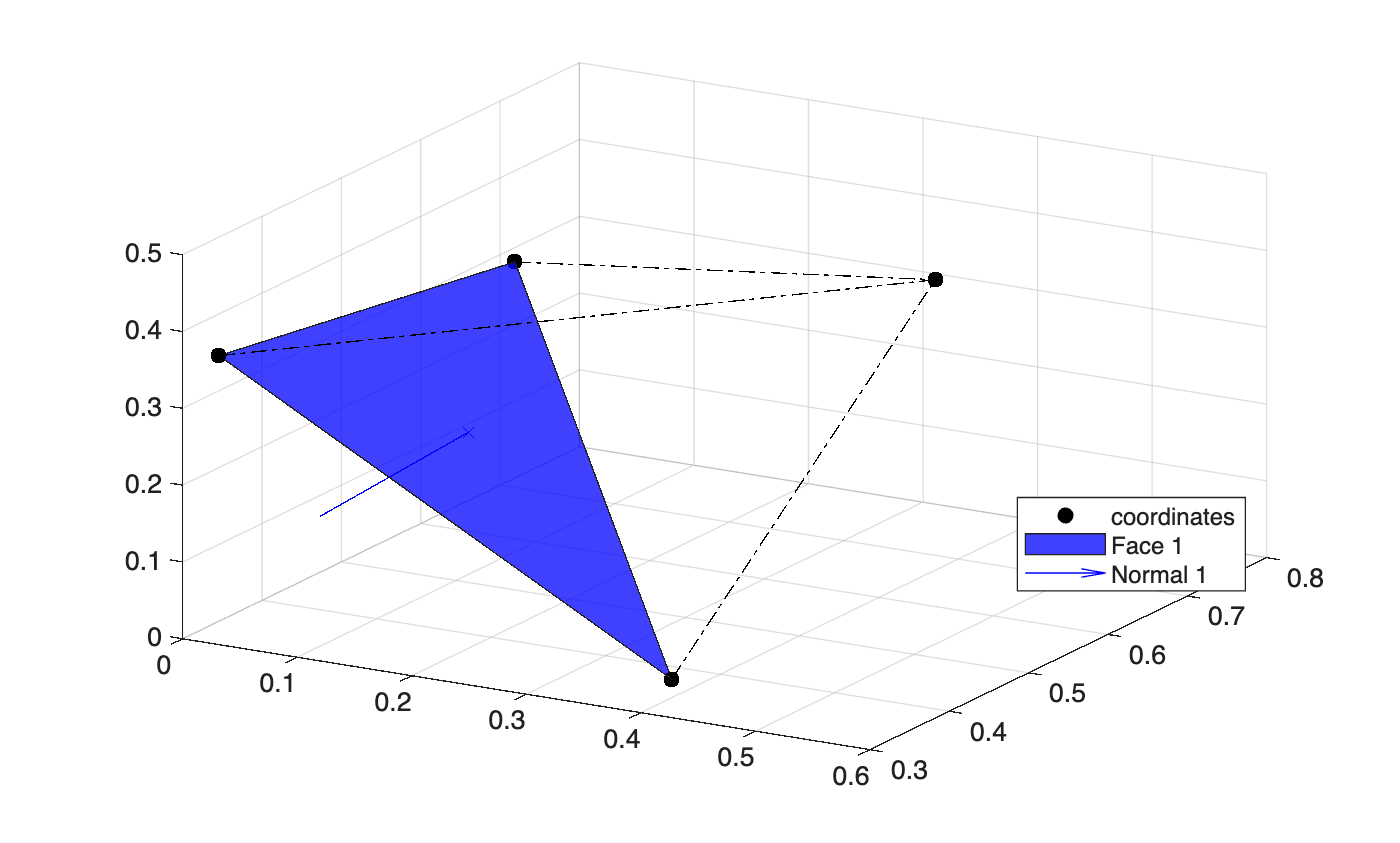

% In this case let's consider the element defined before, First let's
% consider the first face:
% Scatter of the marks for the coordinates
clf('reset')
hold on

% Vertices Scatter: Draw of nodes
scatter3(x, y, z, 'filled', 'k', DisplayName='coordinates')

% Edges definitions
plot3(x([1, 2]), y([1, 2]), z([1, 2]), '-.k', handleVisibility='off')
plot3(x([1, 3]), y([1, 3]), z([1, 3]), '-.k', handleVisibility='off')
plot3(x([1, 4]), y([1, 4]), z([1, 4]), '-.k', handleVisibility='off')

plot3(x([2, 3]), y([2, 3]), z([2, 3]), '-.k', handleVisibility='off')
plot3(x([2, 4]), y([2, 4]), z([2, 4]), '-.k', handleVisibility='off')

plot3(x([3, 4]), y([3, 4]), z([3, 4]), '-.k', handleVisibility='off')

% Faces patching: Order of face
fill3(x([1, 3, 2]), y([1, 3, 2]), z([1, 3, 2]), 'b', ...
                                 FaceAlpha=.75, DisplayName='Face 1')

% Directors of faces: Changes on F1 -> [1 3 2] and F3 -> [1 4 3]
F1_directors = [x(3) - x(1), y(3) - y(1), z(3) - z(1); ...
                x(2) - x(1), y(2) - y(1), z(2) - z(1)];

% Normals to the surfaces
F1_normal = [F1_directors(1, 2)*F1_directors(2, 3) - F1_directors(1, 3)*F1_directors(2, 2), ...
             F1_directors(1, 3)*F1_directors(2, 1) - F1_directors(1, 1)*F1_directors(2, 3), ...
             F1_directors(1, 1)*F1_directors(2, 2) - F1_directors(1, 2)*F1_directors(2, 1)];

% Position of arrows and orientations of faces
plot3(mean(x([1, 2, 3])), mean(y([1, 2, 3])), mean(z([1, 2, 3])), ...
      'xb', handleVisibility='off')
quiver3(mean(x([1, 2, 3])), mean(y([1, 2, 3])), mean(z([1, 2, 3])), ...
        F1_normal(1), F1_normal(2), F1_normal(3), 'b', DisplayName='Normal 1')

legend(location='best')
view([30, 30])
grid on
hold off

% Similarly to the definition made before per face, we need to compute all
% the possible permutations of the face orientation, to assure both basis
% are well defined.
% - This is independent to the definitions made before, for instance we
% need to have clear that the orientations presented indeed shows the
% possible rewriting of the values
points2d=[s,t;...
          t,s;...
          t,1-s-t;...
          s,1-s-t;...
          1-s-t,s;...
          1-s-t,t];

% - Now we define all possible combination of the subsequent products,
% similar to what's been made with the volume functions
db=dubiner2d(2*points2d(:,1)-1,2*points2d(:,2)-1,k);      % 6 * Nnodes x d2

% Same process made with the 3D dubiner, and the matrix it's defined for
% all possible permutations
db=[db(1:Nnodes,:),db(Nnodes+1:2*Nnodes,:),...
    db(2*Nnodes+1:3*Nnodes,:),db(3*Nnodes+1:4*Nnodes,:),...
    db(4*Nnodes+1:5*Nnodes,:),db(5*Nnodes+1:6*Nnodes,:)]; % Nnodes x (6 * d2)

db=bsxfun(@times,weights,db);   % weights formulas times dubiner eval

% Reordering of evaluation of pb to match the definitions
pb=[pb(1:Nnodes,:),pb(Nnodes+1:2*Nnodes,:),...
    pb(2*Nnodes+1:3*Nnodes,:),pb(3*Nnodes+1:4*Nnodes,:)]; % Nnodes x(4 * d3)

allproducts=db'*pb                                        % 6 * d2 x 4 * d3

allproducts =     1.0000    0.0000   -0.0000   -1.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    1.0000    1.0000    0.0000   -0.6667    0.3333    0.0000   -0.0000   -0.0000    0.5000   -0.3333    0.1667    1.0000   -0.3333    0.3333    0.3333    0.1667   -0.1667   -0.1667    0.1667    0.1667    0.1667    1.0000    0.3333    0.3333    0.3333    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667
    0.0000    0.0833    0.2500   -0.0000    0.0000    0.0000   -0.0833    0.0000   -0.2500    0.0000    0.0000    0.1667   -0.0000   -0.0000    0.0000   -0.1333    0.0333    0.0000    0.0000    0.0000    0.0000    0.0833    0.0833    0.3333   -0.0667    0.0000   -0.0833    0.0333    0.1167    0.1667    0.0000    0.0833   -0.0833   -0.3333    0.0667   -0.0000   -0.0833   -0.0333   -0.1167   -0.1667
    0.0000    0.2500   -0.2500   -0.0000    0.0000   -0.0000   -0.2500   -0.0000    0.2500    0.0000    0.0000   -0.0000    0.1667    0.6667   -0.0000    0.0000    0.0000   -0.2000   -

% For instance this result it's particular, if we do the product of the
% orientation 4 and the permutation 3 we end up with
orientation = 4; permutation = 3;                         % Variables selector

db_perm = db(:, 1 + (permutation -1)*d2 :permutation*d2); % db permutation level

pb_ori = pb(:, 1 + (orientation -1)*d3 :orientation*d3 ); % pb permutation level

% Computation per combination
product_ori_perm = db_perm' * pb_ori          % Product of d2 x d3

product_ori_perm =     1.0000    0.3333    0.3333    0.3333    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667
    0.0000   -0.0833    0.2500    0.0000   -0.0667    0.0667   -0.0167    0.1333    0.0500   -0.0000
   -0.0000   -0.0833   -0.0833    0.6667   -0.0667   -0.0667    0.1833   -0.0667    0.1833    0.3333
    0.0000    0.0000    0.0000   -0.0000    0.0111   -0.0556   -0.0000    0.1111    0.0000    0.0000
    0.0000    0.0000   -0.0000    0.0000    0.0111   -0.0111   -0.0667   -0.0222    0.2000    0.0000
    0.0000    0.0000    0.0000   -0.0000    0.0111    0.0111   -0.1000    0.0111   -0.1000    0.5000


This is really important, because we need to be able to localice this value over the all product matrix, this can be done using the indexing defined for the product, for instance, let's search for this value: See that the order follows $\textrm{d2}$ per rows and $\textrm{d3}$ per columns.

% Auxiliar function for indexing of the elements
block2   = @(x) (1+(x-1)*d2):(x*d2);         % Face based indexing: 2D
blockdof = @(x) (1+(x-1)*2*d2):((2*x-1)*d2); % Dof based indexing: 2D
block3   = @(x) (1+(x-1)*d3):(x*d3);         % Element based indexing: 3D

% Product expected from the all products matrix
all_products_pos = allproducts(block2(permutation), block3(orientation))

all_products_pos =     1.0000    0.3333    0.3333    0.3333    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667
    0.0000   -0.0833    0.2500    0.0000   -0.0667    0.0667   -0.0167    0.1333    0.0500   -0.0000
   -0.0000   -0.0833   -0.0833    0.6667   -0.0667   -0.0667    0.1833   -0.0667    0.1833    0.3333
    0.0000    0.0000    0.0000   -0.0000    0.0111   -0.0556   -0.0000    0.1111    0.0000    0.0000
    0.0000    0.0000   -0.0000    0.0000    0.0111   -0.0111   -0.0667   -0.0222    0.2000    0.0000
    0.0000    0.0000    0.0000   -0.0000    0.0111    0.0111   -0.1000    0.0111   -0.1000    0.5000


% This two matrices must be the same
abs(product_ori_perm - all_products_pos)     % Difference near to zero

ans =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


This result it's important, because this envolves the matrices used for the calculation per **orientation, **face considered, and per **permutation, **possible writing of the face basis. Further more this implies that for the calculation of each form we just need to consider the additional values of the form, and the integral on the basis it's done once.

Finally for the integral involving just the values on the faces, we are tempted to consider the orientations per face, in which we find the integrals compatible with each other, for instance consider the integral $\langle \;{\widehat{u} }_h^t \;,\eta {\;\rangle }_{\partial K}$, in which involves a product of the basis: $D\left(x\right)\cdot D\left(x\right)$ let's see how can we do this product, value it's only possible if both permutations are equal, let's consider the all possible results for the permutations involved

permutation_2 = 4; permutation_1 = 4;                           % Variables selector

db_perm_1 = db(:, 1 + (permutation_1 -1)*d2 :permutation_1*d2); % db permutation level
db_perm_2 = db(:, 1 + (permutation_2 -1)*d2 :permutation_2*d2); % db permutation level

% Computation per combination
product_perm1_perm2 = db_perm_1' * db_perm_2                    % Product of d2 x d2

product_perm1_perm2 =     0.0481   -0.0000    0.0012   -0.0029   -0.0000   -0.0079
   -0.0000    0.0056   -0.0000   -0.0000    0.0010    0.0000
    0.0012   -0.0000    0.0174    0.0008   -0.0000   -0.0022
   -0.0029   -0.0000    0.0008    0.0023   -0.0000    0.0003
   -0.0000    0.0010   -0.0000   -0.0000    0.0038   -0.0000
   -0.0079    0.0000   -0.0022    0.0003   -0.0000    0.0118


% How does this product change per permutation used?
permutation_3 = 2; permutation_4 = 2;                          % Variables selector

db_perm_3 = db(:, 1 + (permutation_3 -1)*d2 :permutation_3*d2); % db permutation level
db_perm_4 = db(:, 1 + (permutation_4 -1)*d2 :permutation_4*d2); % db permutation level

% Computation per combination
product_perm3_perm4 = db_perm_3' * db_perm_4                    % Product of d2 x d2

product_perm3_perm4 =     0.0481   -0.0006   -0.0006   -0.0031   -0.0002   -0.0076
   -0.0006    0.0058    0.0001    0.0000    0.0010    0.0002
   -0.0006    0.0001    0.0170    0.0011   -0.0001   -0.0019
   -0.0031    0.0000    0.0011    0.0023   -0.0000    0.0002
   -0.0002    0.0010   -0.0001   -0.0000    0.0037    0.0001
   -0.0076    0.0002   -0.0019    0.0002    0.0001    0.0118


% Are this matrices the same?
abs(product_perm1_perm2 - product_perm3_perm4)                  % Difference near to zero

ans =          0    0.0006    0.0018    0.0002    0.0002    0.0004
    0.0006    0.0001    0.0001    0.0000    0.0001    0.0002
    0.0018    0.0001    0.0004    0.0002    0.0001    0.0003
    0.0002    0.0000    0.0002    0.0000    0.0000    0.0000
    0.0002    0.0001    0.0001    0.0000    0.0001    0.0001
    0.0004    0.0002    0.0003    0.0000    0.0001    0.0000


Even though we have different permutations the final form it's the same for both calculations, for instance we just need to consider 1 possible permutation for all the products independetly of the permutation defined per face, this product takes for instance the orientation of the face, due to the basis defined $A=\left\lbrack A_0 \;|\;A_1 \right\rbrack$.

l = 1; element = 1;                          % Face selection for basis

oneface=T.faces(T.facebyele(element,l),1:3)  % Knots of the face selected

oneface =     38    40    44


% Coordinates related to the face
x=T.coordinates(oneface(:),1);
y=T.coordinates(oneface(:),2);
z=T.coordinates(oneface(:),3);

x12=x(2)-x(1); %x_2-x_1
x13=x(3)-x(1); %x_3-x_1

y12=y(2)-y(1); %y_2-y_1
y13=y(3)-y(1); %y_3-y_1

z12=z(2)-z(1); %z_2-z_1
z13=z(3)-z(1); %z_3-z_1

% The transformation asociated it's defined as:
A_0 = [x12, y12, z12]', A_1 = [x13, y13, z13]'

A_0 =     0.3437
         0
    0.0937


A_1 =     0.3437
    0.2812
    0.3750


With this vectors defined, now we're interested on finding the values of the inner products needed, we might consider:

% Computation of matrix products
A_A = [A_1' * A_1, A_1' * A_0;
       A_0' * A_1, A_0' * A_0;]

A_A =     0.3379    0.1533
    0.1533    0.1270


% Finally to describe the form needed we take
DD = kron(A_A, product_perm1_perm2)

DD =     0.0162   -0.0000    0.0004   -0.0010   -0.0000   -0.0027    0.0074   -0.0000    0.0002   -0.0005   -0.0000   -0.0012
   -0.0000    0.0019   -0.0000   -0.0000    0.0004    0.0000   -0.0000    0.0009   -0.0000   -0.0000    0.0002    0.0000
    0.0004   -0.0000    0.0059    0.0003   -0.0000   -0.0007    0.0002   -0.0000    0.0027    0.0001   -0.0000   -0.0003
   -0.0010   -0.0000    0.0003    0.0008   -0.0000    0.0001   -0.0005   -0.0000    0.0001    0.0004   -0.0000    0.0000
   -0.0000    0.0004   -0.0000   -0.0000    0.0013   -0.0000   -0.0000    0.0002   -0.0000   -0.0000    0.0006   -0.0000
   -0.0027    0.0000   -0.0007    0.0001   -0.0000    0.0040   -0.0012    0.0000   -0.0003    0.0000   -0.0000    0.0018
    0.0074   -0.0000    0.0002   -0.0005   -0.0000   -0.0012    0.0061   -0.0000    0.0002   -0.0004   -0.0000   -0.0010
   -0.0000    0.0009   -0.0000   -0.0000    0.0002    0.0000   -0.0000    0.0007   -0.0000   -0.0000    0.0001    0.0000
    0.0002   -0.0000    0.0

% Following the theorical definitions of each component we can compute,
% using the function:

% Reconstruction of T.perm
T.perm  = T.perm';    % 4 x Nelts

After validating the integral forms we need to achieve, we can now scalate this process using the functions defined:

% ----------------------------- Local solvers definition function ------------------------------ %

% Test element \eta on f: element-wise of the vector
fx_test = testElem(fx,T,k,formulas{1});
fy_test = testElem(fy,T,k,formulas{1});
fz_test = testElem(fz,T,k,formulas{1});

Af=zeros(6*d3,Nelts);           % Storage reservation (6 x d3 x Nelts)

% Storage of vector with impact on the U equation:
Af((0 + 3)*d3+1:(0 + 1 + 3)*d3,:) = fx_test;    % Impact on u -> x coordinate
Af((1 + 3)*d3+1:(1 + 1 + 3)*d3,:) = fy_test;    % Impact on u -> y coordinate 
Af((2 + 3)*d3+1:(2 + 1 + 3)*d3,:) = fz_test;    % Impact on u -> z coordinate

% Computation of the Curl Matrix: Return in the already desired form
% - Computation of Volume Integrals
[Mi, CMx, CMy, CMz] = curlMatrix(T,k,formulas{1});

% - Computation of Faces Integrals
[tauPP, nPP, tauDP, tauDP_t, nDP, tauDD] = matricesFace(T, tau, k, formulas{4});

% Matrices defintions: A solvers local
A1=zeros(6*d3,6*d3,Nelts);    % Solver storage reservation
A2=zeros(6*d3,4*2*d2,Nelts);  % Solver storage reservation

% Matrices defintions: C solvers Flux
CM=zeros(2*4*d2,2*4*d2,Nelts);   % Solver storage reservation
Cf=zeros(2*4*d2,Nelts);          % Solver storage reservation

% Matrices related to solvers

% Definition of the Mass matrix asociated with a_1: 6*d3 x 6*d3
O=zeros(d3,d3,Nelts);   % Big O cero matrix: Shapes juntions

% Block definition of matrix
Mk = [Mi ,O  ,O   ; ...
      O  ,Mi ,O   ; ...
      O  ,O  ,Mi ];

curlPP = [   O,   CMz,  -CMy ; ...
          -CMz,     O,   CMx ; ...
           CMy,  -CMx,    O ];

A1 = [          Mk,    -curlPP ; ...
      curlPP + nPP, Mk + tauPP];

% Definition of  the Mass matrix asociated with a_2: 6*d3 x 2*(4*d2)
% Pendiente la revisión de errores propuesta
A2 = [ permute(nDP, [2 1 3])   ; ...
       permute(tauDP,[2 1 3]) ];

% Definition of the Mass matrix asociated with a_3: 2*(4*d2) x 6*d3
A3 = [nDP, tauDP_t];

% Parallel creation of flux operators
% Revisión del sistema final a generar
parfor i=1:Nelts            
    CM(:,:,i) = A3(:,:,i)/A1(:,:,i) * A2(:,:,i) + tauDD(:, :, i);
    Cf(:,i)   = A3(:,:,i)/A1(:,:,i) * Af(:,i);
end

Now it's time to compute the whole system, for this task we need to recall the geometric elements defined at the start this is going to be done face-wise for the ${\widehat{u} }_h^t \;$degree of freedom system. Recall the definition of the matrices A1, ..., A3, they all were defined using the standard organization defined for the structure `T`, in this case we need to validate that all values are going to be placed on the correct positions. For instance we need to change how the functions behave considering the major changes and fixing of A1 and A0

% Consistency checker: Let's find where the orientations are consistent:
% level / 158 (159 - 242 Boundary)
level = 155; orientation_new = T.orientation;

[row, col] = find(T.facebyele == level), T.orientation(row(1), col(1)), T.orientation(row(2), col(2))

row =     54
    15


col =      2
     3


ans = 1

ans = -1

if mod(sum(col), 2) == 1
    if orientation_new(row(1), col(1)) + orientation_new(row(2), col(2)) == 0
        orientation_new(row(2), col(2)) = orientation_new(row(1), col(1));
    end
end

T.facebyele(row, :)

ans =    241   155   154   156
   121   122   155   123


orientation_new(row, :)

ans =      1     1    -1    -1
     1    -1     1     1


ans = logical
   1


1:Nfaces_free

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


% Now let's do this for all the Free faces on ref to validate the idea
Ndirfaces_id = T_ref.dirfaces(1);  Nfaces_free = Ndirfaces_id -1;

orientation_new = T_ref.orientation;

% Now for all the faces we do:
for face_id=1:Nfaces_free
    
    % Finding of row / col where the face it's located
    [row, col] = find(T_ref.facebyele == face_id);

    % Re-organize of the orientation
    if mod(sum(col), 2) == 1
        if orientation_new(row(1), col(1)) + orientation_new(row(2), col(2)) == 0

            % Exponent of the orientation it's valid
            exponent = T_ref.perm(row(1), col(1)) + T_ref.perm(row(2), col(2)) + 1;
            orientation_new(row(1), col(1)) = (-1)^(exponent) * orientation_new(row(2), col(2));
        end
    end

end

% Validate the sctructure
masking = orientation_new == T_ref.orientation

masking = 24×4 logical array
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1


T_ref.facebyele(~masking)'


ans =

  1×0 empty double row vector



find(sum(~masking, 2) > 0)'


ans =

  1×0 empty double row vector



% Finding of row / col where the face it's located
[row, ~] = find(T_ref.facebyele == 5);

row', T_ref.facebyele(row, :), T_ref.orientation(row, :), orientation_new(row, :), T.perm(row, :)

ans =      9    10


ans =     10    42     5     4
    34    61     5     9


ans =      1     1     1    -1
     1     1    -1    -1


ans =      1     1     1    -1
     1     1    -1    -1


ans =      2     1     1     4
     3     1     6     4


T_ref.facebyele(find(sum(~masking, 2) > 0), :)

ans =     32     3     2     6
    47    11     6     8
    49    14     9    13
    51    22    19    21
    53    30    27    29


T_ref.orientation(find(sum(~masking, 2) > 0), :)

ans =      1     1    -1    -1
     1    -1     1     1
     1    -1     1     1
     1    -1     1     1
     1    -1     1     1


orientation_new(find(sum(~masking, 2) > 0), :)

ans =      1    -1    -1    -1
     1     1    -1     1
     1     1    -1     1
     1     1    -1     1
     1     1    -1     1


% Now we apply the scheme
Ndirfaces_id = T.dirfaces(1);  Nfaces_free = Ndirfaces_id -1;

orientation_new = T.orientation;

% Now for all the faces we do:
for face_id=1:Nfaces_free
    
    % Finding of row / col where the face it's located
    [row, col] = find(T.facebyele == face_id);

    % Re-organize of the orientation
    if mod(sum(col), 2) == 1
        if orientation_new(row(1), col(1)) + orientation_new(row(2), col(2)) == 0

            % Exponent of the orientation it's valid
            exponent = T.perm(row(1), col(1)) + T.perm(row(2), col(2)) + 1;
            orientation_new(row(1), col(1)) = (-1)^(exponent) * orientation_new(row(2), col(2));
        end
    end

end

% Validate the sctructure
masking = orientation_new == T.orientation

masking = 100×4 logical array
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1


T.facebyele(~masking)'


ans =

  1×0 empty double row vector



% Validation of process
level = 100; [row, col] = find(T.facebyele == level);

% Print out
T.facebyele(row, :)

ans =     97    98   100   152
    99   103   153   100


T.orientation(row, :)

ans =     -1    -1     1     1
    -1     1    -1     1


% Recovery of all elements
M=sparse(R(:),C(:),CM(:));

% This step takes 2 things in count:
%  - accumarray(ind, data): sum of common elements defined by the ind
%    and the data array it's the information to operate.
%  - the matrix Cf: Remember it's one of the flux elements defined.
phif=accumarray(RowsRHS,Cf(:));

% Boundary conditions evaluation
% The resulting terms are:
%  - uhartD : Reference term evaluation on the Dirichlet faces
%  - qhatN  : Reference term evaluation on the Neumann faces
%[uhatD,qhatN]=BoundaryConditionn3D(gx, gy, gz, @(x, y, z)0.*x, @(x, y, z)0.*x, @(x, y, z)0.*x, T, k, formulas{4});

% Dirichlet BC: Storage
%uhatD=reshape(uhatD,2*d2*Ndir,1); % uhatD stored as a vector: d2 * Nneu x 1 : todo > Adjust space
Uhatv=zeros(2*d2*Nfaces, 1);      % Storage reservation
%Uhatv(dirfaces)=uhatD;            % Uhat stored as a vector: d2*Nfaces

% RHS Re-assemly
rhs=zeros(2*d2*Nfaces,1);               % Storage reservation: RHS
rhs(free)=phif(free);                   % phi f from accumarray evaluation on free faces
%qhatN=reshape(qhatN,3*d2*Nneu,1);       % qhatN stored as a vector: d2 * Nneu x 1

% Construction of RHS from the equation (5.3) : Denominator terms.
%rhs(neufaces)=rhs(neufaces)+qhatN;      % Perturbation on Neumann faces from the BC3D
rhs=rhs-M(:,dirfaces)*Uhatv(dirfaces);  % Perturbation on Dirichlet faces from the BC3D

% Export of the system
system={M,rhs,free,dirfaces};
solvers={A1,A2,Af};
Uh=[];
Qxh=[];
Qyh=[];
Qzh=[];
Uhat=[];

% RHS currently has the information of the frontier conditions 
% and the information of inner skeleton: solution of uhat
Uhatv(free)=M(free,free)\rhs(free);     % Division by matrix CM (5.3)

Uhat=reshape(Uhatv,2*d2, Nfaces);         % Reshape on d2 x Nfaces (Proyections)
% -------------------------------- Uh Qxh Qyh Qzh ------------------------------ %
% Reconstruction and posprocessing of the skeleton solution to recover
% information on the elements and faces

% Recover of values per elements
faces=T.facebyele'; faces=faces(:);             % Recovery of faces information
uhhataux=reshape(Uhat(:,faces),[2*4*d2,Nelts]); % Reshape on the faces of Uhat
sol=zeros(6*d3,Nelts);                          % Reservation of storage

% Parallel solution of system
parfor K=1:Nelts
    sol(:,K)=A1(:,:,K)\(Af(:,K)-A2(:,:,K)*uhhataux(:,K));
end

% Solution separation on coordinates
Qxh = sol(block3(1),:); Qyh = sol(block3(2),:); Qzh = sol(block3(3),:);
Uxh = sol(block3(4),:); Uyh = sol(block3(5),:); Uzh = sol(block3(6),:);

error_q = errorElem(T,zx,Qxh,k,formulas{1})...
        + errorElem(T,zy,Qyh,k,formulas{1})...
        + errorElem(T,zz,Qzh,k,formulas{1});

error_u = errorElem(T,ux,Uxh,k,formulas{1})...
        + errorElem(T,uy,Uyh,k,formulas{1})...
        + errorElem(T,uz,Uzh,k,formulas{1});

normQ = errorElem(T,zx,zeros(size(Qxh)),k,formulas{1})...
      + errorElem(T,zy,zeros(size(Qxh)),k,formulas{1})...
      + errorElem(T,zz,zeros(size(Qxh)),k,formulas{1});

% Errores en Volumen: Variable auxiliar Z = curl(u)
ErrorQ = [error_q/normQ]

ErrorQ = 13.9278

% Errores en Volumen: Variable U
ErrorU=[error_u/normU]

ErrorU = 84.5852

normUhat   = erroresFace(T, ux, uy, uz,zeros(size(Uhat)),k,formulas{4});
error_uhat = erroresFace(T, ux, uy, uz, Uhat, k,formulas{4});

% Errores en caras: Variable U_hat
ErrorUhat = [error_uhat/normUhat]

ErrorUhat = 1.8080